# **WM9QE: Applied Statistics for Artificial Intelligence**

**Applying Inferential Statistics: Normality & Hypothesis Testing **

This live script includes the examples provided in week 2 for Normal Distribution, Hypothesis Testing and Parametric tests. Each example goes through the following steps:

Full detail of the lectures and examples are availabe on the Moodle page here [Section: Week Two | WM9QE:Applied Statistics for Artificial Intelligence | Moodle@Warwick](https://moodle.warwick.ac.uk/course/section.php?id=621562).

# Section 1. **Normal Distribution and Z-Values in AI System Performance**

Full details for this section are provided in the *Week 2, Session 1* slides available on the Moodle page.

**Learning Objectives: **

- Understand the concept of the Normal distribution and why it’s fundamental in AI systems. 

- Learn to calculate Z-values (standard scores) for standardization. 

- Use MATLAB functions (`normcdf`, `normpdf`) to compute probabilities. 

- Interpret and visualize probability regions on both X (raw) and Z (standardized) scales.

## **Example 1.1**

We are monitoring **AI inference response times**. Each inference takes a slightly different amount of time to complete. On average, our model responds in 1.50 seconds ($\mu =1\ldotp 50$), with a standard deviation of 0.02 seconds ($\sigma =0\ldotp 02$). How can we model this process with the normal distribution?

The response times are **normally distributed** because many small, random variations (e.g., CPU load, network delay, data size) combine to form a bell-shaped pattern.

Our goal: find the probability that a response time is between 1.46s and 1.48s.

A review of key functions and procedures relevant to this section.

clear; clc; close all;   % Clears workspace, command window, and closes figures

**Step 1. Define the population parameters**

mu = 1.50;     % Mean of the population (average response time in seconds)
sigma = 0.02;  % Standard deviation (spread of response times)

fprintf('AI Response Time Distribution Parameters:\n');

AI Response Time Distribution Parameters:


fprintf('Mean (μ) = %.2f s,  Standard Deviation (σ) = %.2f s\n', mu, sigma);

Mean (μ) = 1.50 s,  Standard Deviation (σ) = 0.02 s



% 💡 Explanation:
% μ (mu)  → The *average* expected response time.
% σ (sigma) → How much variation we expect around the mean.
% Most normal data lies within ±3σ of μ.

**Step 2. Compute Z-values and cumulative probabilities for selected response times**

% We’ll analyze several response times (X values):
x_values = [1.44 1.46 1.48 1.50 1.52 1.54 1.56]';

% The Z-score tells us how far each X is from the mean in standard deviations:
z_values = (x_values - mu) / sigma;
% Formula: Z = (X - μ) / σ

% The cumulative probability function (CDF) gives P(X ≤ x)
p_values = normcdf(x_values, mu, sigma);

% MATLAB function: normcdf(X, MU, SIGMA)
% Computes the probability that a normally distributed variable with
% mean MU and standard deviation SIGMA is less than or equal to X.

% Combine results into a table for clarity:
ZTable = table(x_values, z_values, 100*p_values, ...
    'VariableNames', {'ResponseTime_s','Z_value','P(X≤x)_percent'});

disp('--- Normal Distribution and Z-Value Lookup Table ---');

--- Normal Distribution and Z-Value Lookup Table ---


disp(ZTable);

    ResponseTime_s    Z_value    P(X≤x)_percent
    ______________    _______    ______________

         1.44           -3          0.13499    
         1.46           -2            2.275    
         1.48           -1           15.866    
          1.5            0               50    
         1.52            1           84.134    
         1.54            2           97.725    
         1.56            3           99.865    




% This table shows how X maps to Z, and the corresponding cumulative probability.

**Step 3. Compute the probability between two response times**

x_lower = 1.46;    % Lower bound of interest
x_upper = 1.48;    % Upper bound of interest

% Compute cumulative probabilities for both ends
p_lower = normcdf(x_lower, mu, sigma);
p_upper = normcdf(x_upper, mu, sigma);

% Probability of being between them:
p_between = p_upper - p_lower;

% Corresponding standardized Z-scores:
z_lower = (x_lower - mu) / sigma;
z_upper = (x_upper - mu) / sigma;

fprintf('\n--- Probability Between Two Response Times ---\n');


--- Probability Between Two Response Times ---


fprintf('Z(%.2f s) = %.2f → P(X ≤ %.2f) = %.4f (%.2f%%)\n', x_lower, z_lower, x_lower, p_lower, 100*p_lower);

Z(1.46 s) = -2.00 → P(X ≤ 1.46) = 0.0228 (2.28%)


fprintf('Z(%.2f s) = %.2f → P(X ≤ %.2f) = %.4f (%.2f%%)\n', x_upper, z_upper, x_upper, p_upper, 100*p_upper);

Z(1.48 s) = -1.00 → P(X ≤ 1.48) = 0.1587 (15.87%)


fprintf('P(%.2f ≤ X ≤ %.2f) = %.4f (%.2f%%)\n', x_lower, x_upper, p_between, 100*p_between);

P(1.46 ≤ X ≤ 1.48) = 0.1359 (13.59%)



% ✅ Expected result ≈ 13.59%
% This means about 13.6% of responses fall between 1.46s and 1.48s.

**Step 4️. Visualize the Normal Probability Density Function (PDF)**

% Generate X values over ±5σ range for smooth plotting
x = linspace(mu - 5*sigma, mu + 5*sigma, 400)

x =     1.4000    1.4005    1.4010    1.4015    1.4020    1.4025    1.4030    1.4035    1.4040    1.4045    1.4050    1.4055    1.4060    1.4065    1.4070    1.4075    1.4080    1.4085    1.4090    1.4095    1.4100    1.4105    1.4110    1.4115    1.4120    1.4125    1.4130    1.4135    1.4140    1.4145    1.4150    1.4155    1.4160    1.4165    1.4170    1.4175    1.4180    1.4185    1.4190    1.4195    1.4201    1.4206    1.4211    1.4216    1.4221    1.4226    1.4231    1.4236    1.4241    1.4246


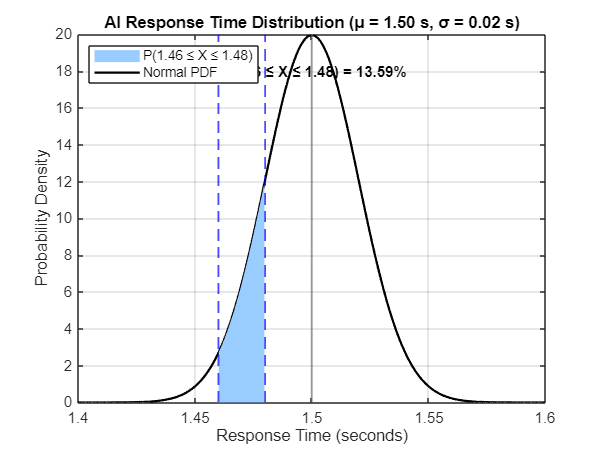


% Compute PDF values for each X
pdf_vals = normpdf(x, mu, sigma);

% MATLAB function: normpdf(X, MU, SIGMA)
%  - Returns the *height* of the probability density function for each X.
%  - Used for visualizing the bell curve.

figure;
plot(x, pdf_vals, 'k', 'LineWidth', 1.5); hold on; grid on;
xlim([mu-5*sigma mu+5*sigma])

% Highlight the probability area between 1.46 and 1.48
mask = (x >= x_lower & x <= x_upper);
area(x(mask), pdf_vals(mask), 'FaceColor', [0.6 0.8 1], 'EdgeColor','none');

% Draw reference lines for mean and bounds
xline(x_lower, '--b', 'LineWidth',1.2);
xline(x_upper, '--b', 'LineWidth',1.2);
xline(mu, '-', 'Color',[0.4 0.4 0.4], 'LineWidth',1);

title('AI Response Time Distribution (μ = 1.50 s, σ = 0.02 s)');
xlabel('Response Time (seconds)');
ylabel('Probability Density');
legend('Normal PDF','P(1.46 ≤ X ≤ 1.48)','Location','northwest');

% Annotate area probability
text(mu, max(pdf_vals)*0.9, sprintf('P(1.46 ≤ X ≤ 1.48) = %.2f%%', 100*p_between), ...
    'HorizontalAlignment','center','FontWeight','bold');

% Explanation:
% The shaded area under the curve represents the *probability* that
% a random response time falls within 1.46s and 1.48s.

**Step 5. Visualize the Standard Normal Distribution (Z-space)**

The same probability region but represented in standardized Z units.

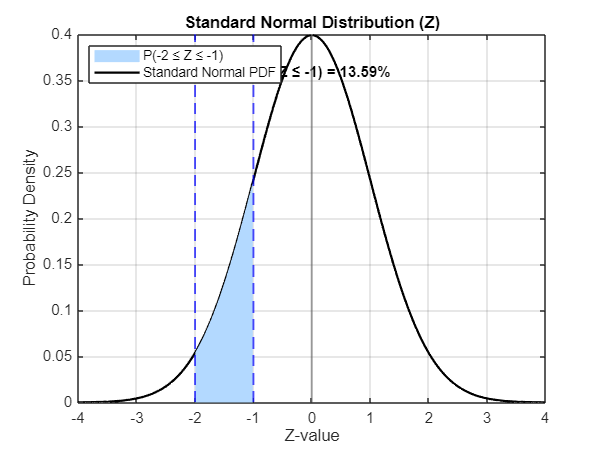

z = linspace(-4, 4, 400);
pdf_z = normpdf(z, 0, 1);  % Standard Normal PDF (mean=0, std=1)

figure%('Color','w','Position',[100 100 900 400]);
plot(z, pdf_z, 'k', 'LineWidth', 1.5); grid on; hold on;

% Highlight the region between Z = -2 and Z = -1
maskZ = (z >= z_lower & z <= z_upper);
area(z(maskZ), pdf_z(maskZ), 'FaceColor', [0.7 0.85 1], 'EdgeColor','none');

% Reference lines
xline(z_lower, '--b', 'LineWidth',1.2);
xline(z_upper, '--b', 'LineWidth',1.2);
xline(0, '-', 'Color',[0.4 0.4 0.4], 'LineWidth',1);

title('Standard Normal Distribution (Z)');
xlabel('Z-value');
ylabel('Probability Density');
legend('Standard Normal PDF','P(-2 ≤ Z ≤ -1)','Location','northwest');

% Annotate with probability
text(0, max(pdf_z)*0.9, sprintf('P(-2 ≤ Z ≤ -1) = %.2f%%', ...
    100*(normcdf(z_upper)-normcdf(z_lower))), ...
    'HorizontalAlignment','center','FontWeight','bold');


% Explanation:
% By converting X → Z, we can use *one universal distribution* (N(0,1))
% for all Normal problems. This is the essence of standardization.

**Step 6️. Key Takeaways**

fprintf('\n--- Key Takeaways ---\n');


--- Key Takeaways ---


fprintf('1. The normal distribution models natural variation in AI response times.\n');

1. The normal distribution models natural variation in AI response times.


fprintf('2️. Z-scores standardize data: Z = (X - μ) / σ.\n');

2️. Z-scores standardize data: Z = (X - μ) / σ.


fprintf('3️. The area under the normal curve represents probability.\n');

3️. The area under the normal curve represents probability.


fprintf('4️. P(X ≤ x) is found using normcdf(x, μ, σ).\n');

4️. P(X ≤ x) is found using normcdf(x, μ, σ).


fprintf('5️. Interval probability P(a ≤ X ≤ b) = normcdf(b) - normcdf(a).\n');

5️. Interval probability P(a ≤ X ≤ b) = normcdf(b) - normcdf(a).


fprintf('6️. Example: P(1.46 ≤ X ≤ 1.48) = %.2f%%.\n', 100*p_between);

6️. Example: P(1.46 ≤ X ≤ 1.48) = 13.59%.


fprintf('7️. This equals the area between Z = -2 and Z = -1 in the standard normal.\n');

7️. This equals the area between Z = -2 and Z = -1 in the standard normal.


fprintf('8️. Understanding this helps AI engineers quantify reliability and latency guarantees.\n');

8️. Understanding this helps AI engineers quantify reliability and latency guarantees.


# Section 2. **Formulating the Hypothesis**

Full details for this section are provided in the *Week 2, Session 1* slides available on the Moodle page.

## Example 2.1 1-Sample Z-Test

**Learning Objectives:** 

- Understand when to use a Z-test (population standard deviation σ known). 

- Apply the Z-test formula to test a hypothesis about a population mean. 

- Compute and interpret p-values, critical regions, and confidence intervals. 

- Use MATLAB statistical functions (`normpdf`, `normcdf`, `norminv`) correctly. 

- Visualise rejection regions and sampling distributions in MATLAB.

Example 2.1 You are the Lead MLOps Engineer for a deployed AI inference system. Historically, the model’s average response time is $\mu ₀=1\ldotp 50s$ with known standard deviation $\sigma =0\ldotp 02s$. After complaints of slower responses, you take a sample of $n=42$ requests with a sample mean $\textrm{\=x}=1\ldotp 507s$. 

Question: Is there significant statistical evidence ($\alpha =0\ldotp 05$, two-tailed) that the average latency has changed? **What is your decision?**

Hypotheses

- $\textrm{H₀}$ : $\mu =1\ldotp 50s$ (no change) 

- $\textrm{H₁}$ : $\mu \not= 1\ldotp 50s$ (mean latency has changed) 

A review of key functions and procedures relevant to this section.

clear; clc; close all;   % Clear workspace, command window, and close figures.

**Step 1️. Define the problem parameters**

mu0   = 1.50;      % Hypothesized population mean (seconds)
sigma = 0.02;      % Known population standard deviation (seconds)
xbar  = 1.507;     % Observed sample mean (seconds)
n     = 42;        % Sample size
alpha = 0.05;      % Significance level (5%)

SE = sigma / sqrt(n);   % Standard error of the mean (σ / √n)

% fprintf prints formatted text to the Command Window
fprintf('--- Step 1: Parameters ---\n');

--- Step 1: Parameters ---


fprintf('μ₀ = %.3f s,  σ = %.3f s,  n = %d,  SE = %.5f s\n\n', mu0, sigma, n, SE);

μ₀ = 1.500 s,  σ = 0.020 s,  n = 42,  SE = 0.00309 s



**Step 2️. Compute the test statistic Z**

Z measures how many standard errors the sample mean is away from μ₀. 


$$ Z = \frac{\bar{X} - \mu_X}{\sigma_X / \sqrt{n}}  = \frac{1.507 - 1.50}{0.02 / \sqrt{42}} $$


Z = (xbar - mu0) / SE;
fprintf('--- Step 2: Test Statistic ---\nZ = %.4f\n\n', Z);

--- Step 2: Test Statistic ---
Z = 2.2683



**Step 3️. Critical values and p-values**

For a two-tailed test:


$$ p = 2 \times [1 - \Phi(|Z|)] $$


where Φ(Z) is the cumulative distribution function (CDF) of the standard normal distribution.

%For α = 0.05, we take 1 − α/2 = 0.975 → zcrit ≈ 1.96.
zcrit = norminv(1 - alpha/2);

% normcdf(z,μ,σ) → returns cumulative probability P(Z ≤ z).
% 1 − normcdf(|Z|) gives the upper-tail probability.
p_one = 1 - normcdf(abs(Z));   % one-tailed p-value
p_two = 2 * p_one;             % two-tailed p-value (both sides)

fprintf('--- Step 3: Critical Values & p-Values ---\n');

--- Step 3: Critical Values & p-Values ---


fprintf('zcrit = ±%.2f,  Observed Z = %.4f\n', zcrit, Z);

zcrit = ±1.96,  Observed Z = 2.2683


fprintf('p(one-tail) = %.4f (%.2f %%)\n', p_one, 100*p_one);

p(one-tail) = 0.0117 (1.17 %)


fprintf('p(two-tail) = %.4f (%.2f %%)\n\n', p_two, 100*p_two);

p(two-tail) = 0.0233 (2.33 %)



**Step 4️. Confidence interval for the mean**


$$95%\textrm{CI}=\textrm{\=x}\pm z_{\textrm{crit}} \times \left(\sigma /√n\right)$$


CI = [xbar - zcrit*SE, xbar + zcrit*SE];
fprintf('--- Step 4: 95 %% Confidence Interval ---\n%.3f ≤ μ ≤ %.3f\n\n', CI(1), CI(2));

--- Step 4: 95 % Confidence Interval ---
1.501 ≤ μ ≤ 1.513



**Step 5️. Decision rule**

if abs(Z) > zcrit
    decision = "Reject H₀ : evidence that mean latency has changed.";
else
    decision = "Fail to reject H₀ : no significant evidence of change.";
end
fprintf('--- Step 5: Decision ---\n%s\n\n', decision);

--- Step 5: Decision ---
Reject H₀ : evidence that mean latency has changed.



**Step 6️. Visual A : Standard Normal Distribution**

`normpdf(x,μ,σ)` → gives the height of the normal PDF at x. Used for plotting the bell curve.

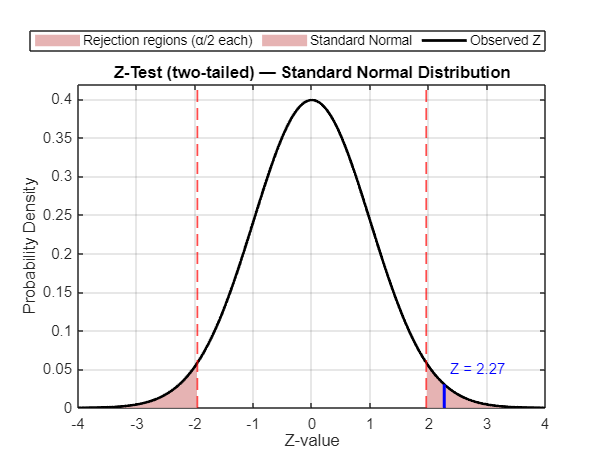

normpdf0 = @(x,mu,s) (1./(s*sqrt(2*pi))) .* exp(-0.5*((x-mu)./s).^2);

z = linspace(-4,4,800);           % Create 800 evenly spaced z-values.
pdf_std = normpdf0(z,0,1);        % Standard normal PDF N(0,1).
Lmask = z <= -zcrit;              % Logical mask for left rejection tail.
Rmask = z >=  zcrit;              % Mask for right tail.

figure
hold on; grid on; box on;

% patch(X,Y,C) fills an area under a curve → used for shading rejection tails.
patch([z(Lmask) fliplr(z(Lmask))],[pdf_std(Lmask) zeros(1,sum(Lmask))],[0.9 0.7 0.7],'EdgeColor','none');
patch([z(Rmask) fliplr(z(Rmask))],[pdf_std(Rmask) zeros(1,sum(Rmask))],[0.9 0.7 0.7],'EdgeColor','none');

plot(z,pdf_std,'k','LineWidth',1.8);         % Main bell curve
xline(-zcrit,'--r','LineWidth',1.2);         % Left critical line
xline( zcrit,'--r','LineWidth',1.2);         % Right critical line
plot([Z Z],[0 normpdf0(Z,0,1)],'b-','LineWidth',2);  % Observed Z line

text(Z+0.1,0.05,sprintf('Z = %.2f',Z),'Color','b');  % Label observed Z

title('Z-Test (two-tailed) — Standard Normal Distribution');
xlabel('Z-value'); ylabel('Probability Density');
legend({'Rejection regions (α/2 each)','Standard Normal','Observed Z'}, ...
       'Location','northoutside','Orientation','horizontal');
ylim([0 max(pdf_std)*1.05]); xlim([-4 4]);

**Step 7️. Visual B : Sampling Distribution of x̄ under H₀**

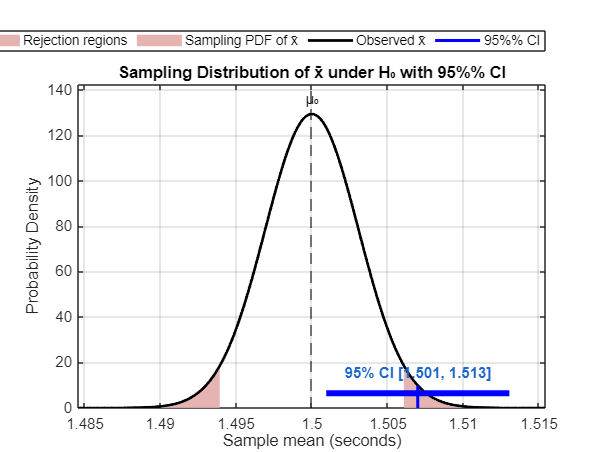

x = linspace(mu0 - 5*SE, mu0 + 5*SE, 800);   % Possible sample means
pdf_xbar = normpdf0(x, mu0, SE);             % Sampling PDF under H₀
xLcut = mu0 - zcrit*SE;                      % Left critical boundary
xRcut = mu0 + zcrit*SE;                      % Right critical boundary

figure
hold on; grid on; box on;

% Shade left rejection region
patch([x(x<=xLcut) fliplr(x(x<=xLcut))],[pdf_xbar(x<=xLcut) zeros(1,sum(x<=xLcut))],[0.9 0.7 0.7],'EdgeColor','none');
% Shade right rejection region
patch([x(x>=xRcut) fliplr(x(x>=xRcut))],[pdf_xbar(x>=xRcut) zeros(1,sum(x>=xRcut))],[0.9 0.7 0.7],'EdgeColor','none');

plot(x,pdf_xbar,'k','LineWidth',1.8);                % Sampling distribution curve
plot([xbar xbar],[0 normpdf0(xbar,mu0,SE)],'b-','LineWidth',2);   % Observed sample mean line
plot([CI(1) CI(2)],[max(pdf_xbar)*0.05 max(pdf_xbar)*0.05],'-b','LineWidth',4); % 95% CI bar
text(mean(CI),max(pdf_xbar)*0.12,sprintf('95%% CI [%.3f, %.3f]',CI(1),CI(2)), ...
    'HorizontalAlignment','center','Color',[0.1 0.4 0.8],'FontWeight','bold');
xline(mu0,'--k'); text(mu0,max(pdf_xbar)*1.05,'μ₀','HorizontalAlignment','center');
xlim([mu0-5*SE mu0+5*SE])
title('Sampling Distribution of x̄ under H₀ with 95%% CI');
xlabel('Sample mean (seconds)'); ylabel('Probability Density');
legend({'Rejection regions','Sampling PDF of x̄','Observed x̄','95%% CI'}, ...
       'Location','northoutside','Orientation','horizontal');
ylim([0 max(pdf_xbar)*1.1]);

**Step 8️. Interpretation and Theory Recap**

fprintf('--- Step 8: Interpretation ---\n');

--- Step 8: Interpretation ---


fprintf('Z = %.4f, p(two-tail)=%.4f, α=%.2f → %s\n', Z, p_two, alpha, decision);

Z = 2.2683, p(two-tail)=0.0233, α=0.05 → Reject H₀ : evidence that mean latency has changed.


fprintf('95%% CI for μ: [%.3f, %.3f]\n\n', CI(1), CI(2));

95% CI for μ: [1.501, 1.513]



fprintf('--- Theory Recap ---\n');

--- Theory Recap ---


fprintf('• Use Z-test when σ (population std) is known and n≥30 or normal population.\n');

• Use Z-test when σ (population std) is known and n≥30 or normal population.


fprintf('• Z = (x̄ − μ₀)/(σ/√n) follows N(0,1) under H₀.\n');

• Z = (x̄ − μ₀)/(σ/√n) follows N(0,1) under H₀.


fprintf('• Reject H₀ if |Z| > zcrit or p < α.\n');

• Reject H₀ if |Z| > zcrit or p < α.


fprintf('• 95%% CI = x̄ ± zcrit×(σ/√n).\n');

• 95% CI = x̄ ± zcrit×(σ/√n).


fprintf('• normpdf(x,μ,σ) returns PDF height at x.\n');

• normpdf(x,μ,σ) returns PDF height at x.


fprintf('• normcdf(x,μ,σ) returns P(X ≤ x).\n');

• normcdf(x,μ,σ) returns P(X ≤ x).


fprintf('• norminv(p,μ,σ) returns the quantile where P(X ≤ x)=p.\n');

• norminv(p,μ,σ) returns the quantile where P(X ≤ x)=p.


fprintf('• In AI monitoring, Z-tests help detect drift in model latency or accuracy.\n');

• In AI monitoring, Z-tests help detect drift in model latency or accuracy.


fprintf('• Larger n → smaller SE → tighter confidence intervals.\n');

• Larger n → smaller SE → tighter confidence intervals.


## **Example 2.2 1-Sample t-Test**

**Learning Objectives: **By the end of this practical session, you should be able to:

- Explain the purpose of a **one-sample *****t*****-test** and its assumptions.

- Compute key **descriptive statistics** (mean, variance, standard error, etc.).

- Conduct a **manual one-sample *****t*****-test** and interpret the results.

- Compute and visualize **confidence intervals** and **rejection regions**.

- Summarize and interpret findings in plain language for decision-making.

**Example 2.2: **A company has developed its budget on the basis that the average revenue from individual customers will be 200£. The finance department took a random sample of annual revenues from 15 customers. Should the logic of the budget be revised for an α = 0.05?

**Solution: **We are testing whether the **true mean annual revenue** differs from £200.

**Hypotheses:**

- $H_0$: $\mu =200$ (budget assumption holds)

- $H_1$: $\mu \not= 200$ (budget assumption may be invalid)

Goal: Determine whether the average customer revenue differs from £200 using a two-tailed one-sample t-test (α = 0.05).�

A review of key functions and procedures relevant to this section.

clear; clc; close all;

**Step 1. Input Data and Parameters**

Hypothesized population mean (μ0) = 200 Significance level α = 0.05

alpha  = 0.05;
mu0    = 200;

% Revenue data from 15 randomly selected customers (£)
revenues = [170, 224, 239, 195, 144, 182, 160, 125, 170, 229, 218, 200, 231, 210, 180];

**Step 2. Descriptive Statistics**

n    = numel(revenues);           % Sample size
xbar = mean(revenues);            % Sample mean
s    = std(revenues, 0);          % Sample standard deviation (n-1)
SE   = s / sqrt(n);               % Standard error
df   = n - 1;                     % Degrees of freedom

% Additional descriptive measures
medianVal = median(revenues);
modeVal   = mode(revenues);
variance  = var(revenues);
rangeVal  = range(revenues);
minVal    = min(revenues);
maxVal    = max(revenues);
sumVal    = sum(revenues);

**Step 3. Display Descriptive Results**

fprintf('\n--- Step 1: Descriptive Statistics ---\n');


--- Step 1: Descriptive Statistics ---


fprintf('Sample size (n): %d\n', n);

Sample size (n): 15


fprintf('Mean (x̄): £%.2f\n', xbar);

Mean (x̄): £191.80


fprintf('Median: £%.2f | Mode: £%.2f\n', medianVal, modeVal);

Median: £195.00 | Mode: £170.00


fprintf('Standard deviation (s): %.3f\n', s);

Standard deviation (s): 34.042


fprintf('Standard error (SE): %.3f\n', SE);

Standard error (SE): 8.790


fprintf('Variance: %.3f | Range: %.2f | Min: %.2f | Max: %.2f\n', variance, rangeVal, minVal, maxVal);

Variance: 1158.886 | Range: 114.00 | Min: 125.00 | Max: 239.00


fprintf('Sum: %.2f | Degrees of freedom: %d\n', sumVal, df);

Sum: 2877.00 | Degrees of freedom: 14


**Step 4. Histogram and boxplot to explore distribution**

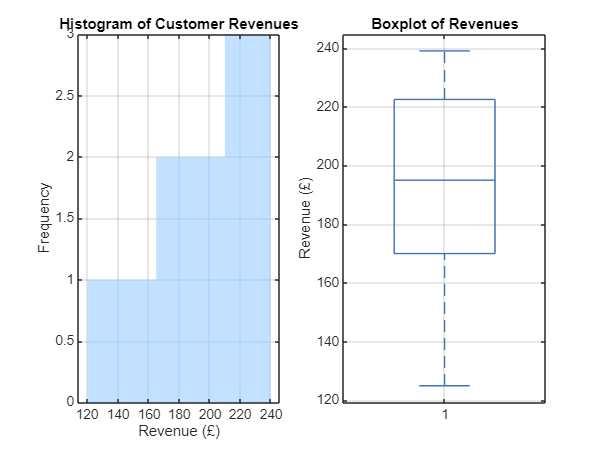

figure;%('Name','Descriptive Plots','Color','w')
subplot(1,2,1)
histogram(revenues, 8, 'FaceColor',[0.6 0.8 1], 'EdgeColor','none');
xlabel('Revenue (£)'); ylabel('Frequency');
title('Histogram of Customer Revenues'); grid on;

subplot(1,2,2)
boxplot(revenues, 'Colors',[0.25 0.45 0.7], 'Widths',0.5);
ylabel('Revenue (£)'); title('Boxplot of Revenues'); grid on;

**Step 5. One-Sample t-Test (Manual Calculation)**

Compute t-statistic. **Test Statistic:  **$t=\frac{\bar{x} -\mu_0 }{\hat{\sigma} /\sqrt{n}}$, where $\bar{x}$ is the sample mean, $\hat{\sigma}$ is the sample standard deviation, $n$ is sample size and the Degrees of freedom is n-1. Decision rule:

- If $\left|t\right|>t_{\textrm{critical}}$ or $p<\alpha$: Reject $H_0$

- Otherwise: Fail to reject $H_0$

t_stat = (xbar - mu0) / SE;
% Two-tailed p-value
if exist('tcdf','file')==2
    p_two = 2 * (1 - tcdf(abs(t_stat), df));
else
    p_two = 2 * (1 - normcdf(abs(t_stat), 0, 1));
end
% Critical t-value (two-tailed)
if exist('tinv','file')==2
    t_crit = tinv(1 - alpha/2, df);
else
    t_crit = norminv(1 - alpha/2, 0, 1);
end

% 95% Confidence Interval for μ
CI = [xbar - t_crit*SE, xbar + t_crit*SE];
% Decision Rule
if p_two < alpha
    decision = "Reject H0 (evidence mean ≠ £200)";
else
    decision = "Fail to reject H0 (no significant difference)";
end

**Step 6. Display t-Test Results**

fprintf('\n--- One-Sample t-Test Results ---\n');


--- One-Sample t-Test Results ---


fprintf('t-statistic = %.4f | df = %d\n', t_stat, df);

t-statistic = -0.9329 | df = 14


fprintf('Two-tailed p-value = %.4f\n', p_two);

Two-tailed p-value = 0.3667


fprintf('t-critical (α=%.2f) = ±%.3f\n', alpha, t_crit);

t-critical (α=0.05) = ±2.145


fprintf('95%% Confidence Interval for μ: [£%.2f, £%.2f]\n', CI(1), CI(2));

95% Confidence Interval for μ: [£172.95, £210.65]


fprintf('Decision: %s\n', decision);

Decision: Fail to reject H0 (no significant difference)



% Summarize in a table
ResultsTable = table(n, xbar, s, SE, df, t_stat, t_crit, p_two, ...
                     CI(1), CI(2), string(decision), ...
    'VariableNames', {'n','Mean','StdDev','StdError','df','t_stat','t_crit', ...
                      'p_value','CI_Lower','CI_Upper','Decision'});
disp(ResultsTable);

    n     Mean     StdDev    StdError    df     t_stat     t_crit    p_value    CI_Lower    CI_Upper                       Decision                    
    __    _____    ______    ________    __    ________    ______    _______    ________    ________    _______________________________________________

    15    191.8    34.042     8.7897     14    -0.93291    2.1448    0.36668     172.95      210.65     "Fail to reject H0 (no significant difference)"



**Step 7. Visualize the t-Distribution**

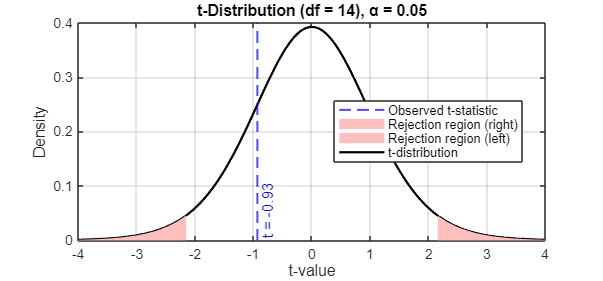

x = linspace(-4,4,400);
if exist('tpdf','file')==2
    pdf_t = tpdf(x, df);
else
    pdf_t = normpdf(x, 0, 1);
end

figure('Color','w','Position',[100 100 900 420]);
plot(x, pdf_t, 'k', 'LineWidth', 1.5); hold on; grid on;

% Rejection regions (α/2 each side)
idxL = x < -t_crit; idxR = x > t_crit;
area(x(idxL), pdf_t(idxL), 'FaceColor',[1 0.75 0.75], 'EdgeColor','none');
area(x(idxR), pdf_t(idxR), 'FaceColor',[1 0.75 0.75], 'EdgeColor','none');

% Observed t-statistic line
xline(t_stat, '--b', sprintf('t = %.2f', t_stat), 'LineWidth',1.3, ...
    'LabelVerticalAlignment','bottom');

xlabel('t-value'); ylabel('Density');
title(sprintf('t-Distribution (df = %d), α = %.2f', df, alpha));
legend('t-distribution','Rejection region (left)','Rejection region (right)',...
       'Observed t-statistic','Location','best');

**Step 8. Interpretation (Plain English)**

fprintf('\n--- Step 3: Interpretation ---\n');


--- Step 3: Interpretation ---


fprintf('Sample mean = £%.2f (n = %d) vs. hypothesized mean = £%.0f\n', xbar, n, mu0);

Sample mean = £191.80 (n = 15) vs. hypothesized mean = £200


fprintf('t = %.4f, p = %.4f\n', t_stat, p_two);

t = -0.9329, p = 0.3667


if p_two < alpha
    fprintf('→ Reject H0: There is statistically significant evidence that the average revenue differs from £%.0f.\n', mu0);
else
    fprintf('→ Fail to reject H0: There is no significant evidence that the average revenue differs from £%.0f.\n', mu0);
end

→ Fail to reject H0: There is no significant evidence that the average revenue differs from £200.


fprintf('95%% CI for μ = [£%.2f, £%.2f]\n', CI(1), CI(2));

95% CI for μ = [£172.95, £210.65]


# **Section 3 Test for Normality**

Full details for this section are provided in the *Week 2, Session 1* slides available on the Moodle page.

**Learning objectives: **By the end of this practical session, you will be able to:

- Explain the **purpose of the χ² goodness-of-fit test** in assessing Normality.

- Compute **descriptive statistics** (mean, std, quartiles, IQR, skewness, kurtosis).

- Apply **Sturges’ rule** to determine the number of histogram bins.

- Derive **expected frequencies** from the Normal CDF using MATLAB functions.

- Calculate and interpret the **χ² statistic**, **degrees of freedom**, and **p-value**.

- Make data-driven **decisions about Normality** and visualize results with boxplots and histograms.

- Relate these techniques to **real-world applications** such as AI model validation, quality control, and anomaly detection.

**AI & Data Science Application: **This same statistical check is essential in **AI system performance validation, **for example:

- Checking if **inference latency** or **training losses** are approximately Normal before applying parametric confidence intervals.

- Verifying that **sensor noise** or **model errors** follow assumed Normal patterns in production ML pipelines.

Ensuring Normality supports **reliable hypothesis testing, confidence estimation**, and **robust model monitoring**.

## **Example 3.1 **Normality Check (χ² “Goodness of Fit”) 

**Example Normality Check of Iron Stick Lengths:**  A manufacturing company produces iron sticks for construction. Customers request 19.5 ± 4.5 m. Complaints arose, so we test whether product lengths follow a **Normal Distribution** (key assumption for quality and process control).

- Null Hypothesis ($H_0$): Data come from a Normal(μ̂, σ̂) 

- Alternative ($H_1$): Data do not follow a Normal distribution.

Key MATLAB Functions used:

clear; clc; close all;

**Step 1. Input Sample Data**

A sample of n = 20 iron stick lengths (in meters)

length_m = [17.3, 14.5, 17.5, 18.6, 18.0, 19.2, 19.0, 16.4, ...
             21.2, 20.3, 20.6, 18.4, 22.1, 21.3, 14.4, 14.9, ...
             20.0, 18.4, 20.8, 18.3]';

n = numel(length_m);  % numel() counts total observations
fprintf('Sample size n = %d\n', n);

Sample size n = 20


**Step 2, Descriptive Statistics**

Compute key descriptive measures to summarize data shape

MeanVal   = mean(length_m);           % Sample mean
StdVal    = std(length_m, 0);         % Sample std (n-1 denominator)
MedianVal = median(length_m);         % Middle value
VarVal    = var(length_m, 0);         % Sample variance
KurtVal   = kurtosis(length_m) - 3;   % Excess kurtosis (like Excel)
SkewVal   = skewness(length_m);       % Measure of asymmetry
MinVal    = min(length_m);
MaxVal    = max(length_m);
RangeVal  = range(length_m);          % Max - Min
mu = MeanVal;
sigma = StdVal;

% Quartiles and IQR
Q1  = prctile(length_m,25);           % 25th percentile
Q2  = prctile(length_m,50);           % Median
Q3  = prctile(length_m,75);           % 75th percentile
IQRv = Q3 - Q1;                       % Interquartile range

% Outlier boundaries (Tukey's rule)
LowerBound = Q1 - 1.5 * IQRv;
UpperBound = Q3 + 1.5 * IQRv;

% Display all descriptive stats in a table
DescStats =array2table( [MeanVal; StdVal; MedianVal; VarVal; KurtVal; SkewVal; ...
    RangeVal; Q1; Q2; Q3; IQRv; LowerBound; UpperBound], 'RowNames', ...
    {'MeanVal', 'StdVal', 'MedianVal', 'VarVal', 'KurtVal', 'SkewVal', ...
    'RangeVal', 'Q1', 'Q2', 'Q3', 'IQRv', 'LowerBound', 'UpperBound'});
disp(DescStats)

                    Var1  
                  ________

    MeanVal          18.56
    StdVal          2.2582
    MedianVal         18.5
    VarVal          5.0994
    KurtVal       -0.66826
    SkewVal       -0.42087
    RangeVal           7.7
    Q1                17.4
    Q2                18.5
    Q3               20.45
    IQRv              3.05
    LowerBound      12.825
    UpperBound      25.025



**Step 3. Determine Bins using Sturges’ Rule**

Sturges' formula: $k=1+3\ldotp 322*\textrm{log10}\left(n\right)$

k = round(1 + 3.322 * log10(n));  % Number of bins (rounded)
ClassRange = (MaxVal - MinVal) / k;  % Bin width
% we have a frequency which is higher than the classes, so we have to
% include it in a new bin and now we have 6 bins
edges = MinVal:ClassRange:(MaxVal + ClassRange);
centers = edges(1:end-1) + ClassRange/2;  % Bin midpoints

fprintf('\nNumber of classes = %d, Class range = %.2f\n', k, ClassRange);


Number of classes = 5, Class range = 1.54


**Step 4. Visualization**

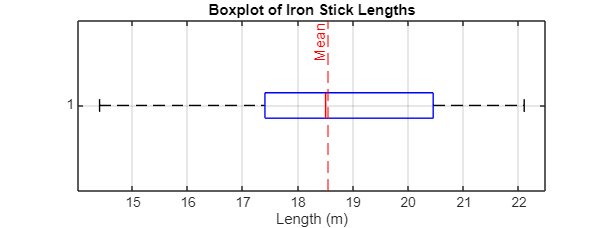

figure('Color','w','Position',[100 100 950 360]);

% --- Boxplot (detect outliers, spread, symmetry)
boxplot(length_m, 'orientation', 'horizontal');
hold on;
xline(MeanVal,'r--','Mean','LabelHorizontalAlignment','left');
xline(LowerBound,'k:','Lower Bound');
xline(UpperBound,'k:','Upper Bound');
title('Boxplot of Iron Stick Lengths');
xlabel('Length (m)');
grid on; hold off;

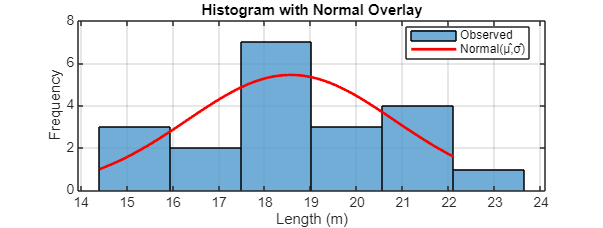


% --- Histogram with Normal PDF overlay
histogram(length_m, 'BinEdges', edges, ...
    'FaceColor', [0.3 0.6 0.8], 'FaceAlpha', 0.8);
hold on;

% normpdf() computes Normal probability density
x = linspace(MinVal, MaxVal, 400);
y = normpdf(x, mu, sigma) * n * ClassRange;  % Scale PDF to frequency scale
plot(x, y, 'r-', 'LineWidth', 1.8);

title('Histogram with Normal Overlay');
xlabel('Length (m)'); ylabel('Frequency');
legend('Observed','Normal(μ̂,σ̂)','Location','best');
grid on; hold off;

**Step 5. Observed Frequencies**

`histcounts()` counts how many data points fall into each bin

[counts, ~] = histcounts(length_m, edges);
LengthBins = centers';
Frequency  = counts';
Table_Observed = table(LengthBins, Frequency)

Table_Observed = 6×2 table
    LengthBins    Frequency
    __________    _________

      15.17           3    
      16.71           2    
      18.25           7    
      19.79           3    
      21.33           4    
      22.87           1    


**Step 6. Expected Frequencies under Normal(μ̂, σ̂)**

For each bin $\left\lbrack a_i ,b_i \right)$, the expected probability is calculated as:$P_i =F\left(b_i \right)-F\left(a_i \right)$

where $F\left(x\right)=\textrm{normcdf}\left(x,\hat{\mu} ,\hat{\sigma} \right)$

Expected count in each bin:$E_i =n\times P_i$

% normcdf() gives cumulative probability of the Normal distribution
cdf_edges = normcdf(edges, mu, sigma);

% diff() computes differences between consecutive CDF values
bin_prob = diff(cdf_edges);

% Expected count = n × Pᵢ
expected = n * bin_prob;

fprintf('\nSum Observed = %.3f, Sum Expected = %.3f\n', sum(Frequency), sum(expected));


Sum Observed = 20.000, Sum Expected = 19.101


**Step 7. χ² Contributions and Test Statistic**

χ² contribution for each bin: (Observed - Expected)² / Expected

chi_contrib = (Frequency - expected').^2 ./ expected';

Chi2Table = table(LengthBins, Frequency, bin_prob', expected', chi_contrib, ...
    'VariableNames', {'BinCenter','Observed','BinProb','Expected','Chi2Contribution'})

Chi2Table = 6×5 table
    BinCenter    Observed    BinProb     Expected    Chi2Contribution
    _________    ________    ________    ________    ________________

      15.17         3        0.090255     1.8051          0.79099    
      16.71         2         0.19325     3.8651          0.89999    
      18.25         7         0.26448     5.2895          0.55313    
      19.79         3         0.23139     4.6279          0.57262    
      21.33         4         0.12941     2.5883          0.76997    
      22.87         1        0.046246    0.92492        0.0060946    



Chi2_Stat = sum(chi_contrib);  % χ² statistic
df = k - 1 - 2;                % Subtract 2 estimated parameters (μ, σ)
p_val = 1 - chi2cdf(Chi2_Stat, df);  % Right-tail p-value using chi2cdf()

fprintf('\nChi-square Statistic = %.3f\nDegrees of Freedom = %d\np-value = %.3f\n', ...
    Chi2_Stat, df, p_val);


Chi-square Statistic = 3.593
Degrees of Freedom = 2
p-value = 0.166


**Step 8. Decision at α = 0.05**

alpha = 0.05;
if p_val > alpha
    decision = "Fail to reject H₀ → Data consistent with Normality.";
else
    decision = "Reject H₀ → Data deviate from Normality.";
end
fprintf('\nDecision: %s\n', decision);


Decision: Fail to reject H₀ → Data consistent with Normality.


**Step 9. Interpretation**

fprintf('\n--- Interpretation ---\n');


--- Interpretation ---


fprintf('χ²(%d) = %.3f, p = %.3f\n', df, Chi2_Stat, p_val);

χ²(2) = 3.593, p = 0.166


fprintf('→ %s\n', decision);

→ Fail to reject H₀ → Data consistent with Normality.


fprintf('Conclusion: The χ² test suggests %s\n', lower(decision));

Conclusion: The χ² test suggests fail to reject h₀ → data consistent with normality.



mu = MeanVal; 
sigma = StdVal;
cdf_edges = normcdf(edges, mu, sigma);
bin_prob = diff(cdf_edges); %alculates differences between adjacent elements of cdf_edges.
expected = n * bin_prob; %Expected count in each bin:n*bin_prob

% Verify sums
fprintf('\nSum Observed = %.3f, Sum Expected = %.3f\n', sum(Frequency), sum(expected));


Sum Observed = 20.000, Sum Expected = 19.101


# Section 4. Parametric Tests

## Example 4.1 F-Test

Economics received complaints that male and female public sector employees might have different variability in their salaries. To investigate, random samples were collected: Sample 1: Salaries of Male Employees (€) Sample 2: Salaries of Female Employees (€) We test whether the two populations have equal variances.

Hypotheses: 

- H0: σ₁² = σ₂² (variances are equal) 

- H1: σ₁² ≠ σ₂² (variances differ)

Test Type: Two-tailed F-Test (α = 0.05). This test is used BEFORE 2-sample t-tests, to decide whether to assume equal variances (pooled t-test) or not (Welch’s test).

**Learning Outcomes** After completing this exercise, you will be able to: 

- ️Understand the logic and purpose of the F-test for comparing variances. 

- Compute the F statistic and interpret its meaning. 

- Obtain one- and two-tailed p-values using `fcdf()`. 

- Identify critical F values using` finv()`. 

- Visualise F distribution with rejection regions. 

- Interpret and communicate results clearly

**Detailed Breakdown of Core MATLAB Functions**

**Step 0. Initialization**

clear; clc; close all; 
% clear: removes variables from the workspace to avoid contamination.
% clc: clears the command window for a clean start.
% close all: closes any previously open figure windows.

**Step 1. Input data**

% Male salaries (25 obs) and Female salaries (23 obs)
salary_M = [41324.8 48981.2 46244.3 45907.6 39473.4 45970.6 46835.3 45856.4 ...
            45913.8 56185.1 38261.4 55075.1 45364.6 41486.7 49027.9 38621.5 ...
            41950.7 32228.6 50662.3 46330.7 36324.5 39874.2 54694.8 52152.8 52744.3];

salary_F = [37915.9 26981.5 22803.0 32279.8 44772.5 32336.9 42252.8 38217.0 ...
            35054.4 40877.2 32673.0 42463.2 37821.8 38746.1 34626.6 20007.8 ...
            36671.8 45671.9 18093.7 52163.6 43207.3 36158.7 52314.6];

% Sample sizes and degrees of freedom:
nM  = numel(salary_M);   % number of male salary observations
nF  = numel(salary_F);   % number of female salary observations
dfM = nM - 1;            % degrees of freedom for sample variance (male)
dfF = nF - 1;            % degrees of freedom for sample variance (female)

fprintf('--- SAMPLE DETAILS ---\n');

--- SAMPLE DETAILS ---


fprintf('Male:   n = %d, df = %d\n', nM, dfM);

Male:   n = 25, df = 24


fprintf('Female: n = %d, df = %d\n\n', nF, dfF);

Female: n = 23, df = 22




% Why this matters:
% F-tests compare *ratios of sample variances*. Both samples must be:
% - Independent (no overlap of individuals)
% - Approximately normally distributed

**Why this matters**

- F-tests require **two independent samples** and their **sample variances** with $\textrm{df}=n-1$.

**Step 2. Descriptive statistics**

Compute basic summary statistics for both groups to provide context.

fmt = @(x) round(x,4);  % simple rounding function for cleaner display

% Central tendency and spread
mean_M   = mean(salary_M);      % mean salary (male)
mean_F   = mean(salary_F);      % mean salary (female)
std_M    = std(salary_M);       % sample standard deviation (denominator n−1)
std_F    = std(salary_F);
var_M    = var(salary_M);       % sample variance
var_F    = var(salary_F);
se_M     = std_M/sqrt(nM);      % standard error of the mean
se_F     = std_F/sqrt(nF);
median_M = median(salary_M);    % median salary
median_F = median(salary_F);
min_M    = min(salary_M);       % smallest salary (male)
max_M    = max(salary_M);       % largest salary (male)
min_F    = min(salary_F);       % smallest salary (female)
max_F    = max(salary_F);       % largest salary (female)
range_M  = max_M - min_M;       % range = max - min
range_F  = max_F - min_F;
sum_M    = sum(salary_M);       % total salaries (male)
sum_F    = sum(salary_F);       % total salaries (female)

% Organize results into a readable summary table
row_names = {'Mean','Std_Error','Median','Std_Dev','Variance', ...
             'Min','Max','Range','Sum','Count'};

male_stats   = [mean_M; se_M; median_M; std_M; var_M; min_M; max_M; range_M; sum_M; nM];
female_stats = [mean_F; se_F; median_F; std_F; var_F; min_F; max_F; range_F; sum_F; nF];

Desc = array2table([fmt(male_stats) fmt(female_stats)], ...
                   'VariableNames', {'Salary_M','Salary_F'}, ...
                   'RowNames', row_names);

disp('--- DESCRIPTIVE STATISTICS ---');

--- DESCRIPTIVE STATISTICS ---


disp(Desc);

                  Salary_M      Salary_F 
                 __________    __________

    Mean              45500         36700
    Std_Error        1235.7        1852.3
    Median            45914         37822
    Std_Dev          6178.7        8883.5
    Variance     3.8176e+07    7.8916e+07
    Min               32229         18094
    Max               56185         52315
    Range             23956         34221
    Sum          1.1375e+06    8.4411e+05
    Count                25            23




% What’s happening here:
% - mean/std/var etc. are descriptive statistics
% - array2table() formats them for display
% - This gives us a quick numeric summary before the hypothesis test

**What these functions do**

- `mean/std/var/median/min/max/sum` are standard statistics.

- `array2table` converts numeric arrays into a table for readable display.

- `fmt` is a simple anonymous function to round values consistently.

**Step 3. Visual exploration: Boxplots and Histograms**

Always visualize data before testing to check approximate normality and see whether the variances look visually different.

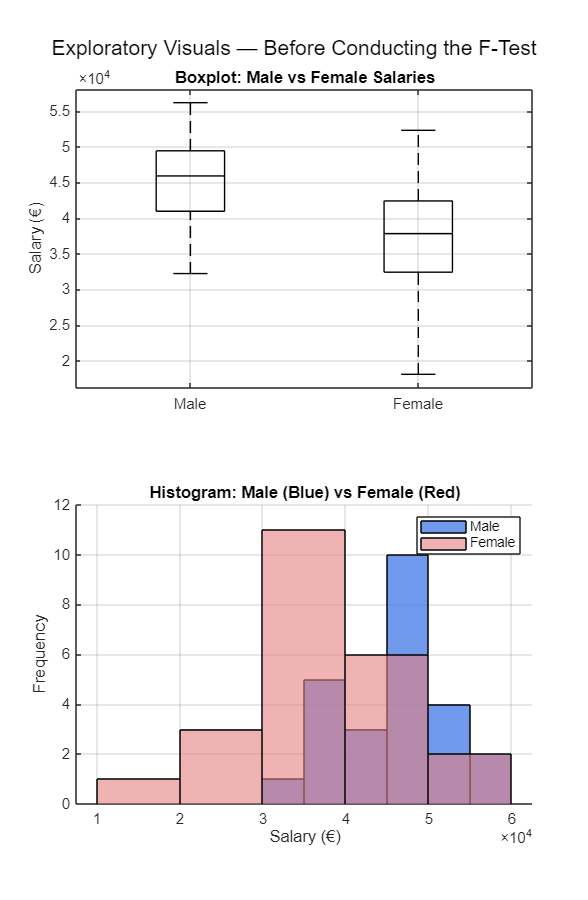

figure('Color','w','Position',[100 100 980 1500]);

% ---- (a) Boxplots ----
subplot(2,1,1);
group_labels = [repmat({'Male'}, nM, 1); repmat({'Female'}, nF, 1)];
all_salaries = [salary_M salary_F]';   % stack the two samples

% boxplot(y,group): draws separate boxplots for each group.
boxplot(all_salaries, group_labels, 'Colors','k', 'Whisker',1.5);
ylabel('Salary (€)');
title('Boxplot: Male vs Female Salaries');
grid on;

% ---- (b) Histograms ----
subplot(2,1,2); hold on;
histogram(salary_M, 'Normalization','count', 'FaceColor',[0.3 0.5 0.9], 'FaceAlpha',0.8);
histogram(salary_F, 'Normalization','count', 'FaceColor',[0.9 0.5 0.5], 'FaceAlpha',0.6);
xlabel('Salary (€)'); ylabel('Frequency');
title('Histogram: Male (Blue) vs Female (Red)');
legend('Male','Female');
grid on;

sgtitle('Exploratory Visuals — Before Conducting the F-Test');


% Interpretation:
% Boxplots and histograms allow you to visually compare the *spread* 
% (variability) of each group. The F-test will formalize this comparison.

**What these functions do**

- `boxplot(y,group)` draws side-by-side boxplots by group.

- `repmat(cellstr, n, 1)` repeats group labels to match each observation.

- `histogram(x, ...)` displays a distribution; `FaceAlpha` controls transparency.

- `sgtitle` creates a shared title for a figure with subplots.

**Step 4. Compute p-values and Critical F Values**

The F statistic is the ratio of the two sample variances. By convention, the **larger variance** is placed in the numerator, but you must be consistent with your critical value lookup.

F_stat = var_M / var_F;     % ratio of variances (Male / Female)

% One-tail p-value: probability that an F random variable ≤ F_obs
p_one = fcdf(F_stat, dfM, dfF);

% Two-tailed p-value = 2 × smaller tail
p_two = 2 * min(p_one, 1 - p_one);

% Critical F values (for α = 0.05, two-tailed test → 0.025 each tail)
Fcrit_low2 = finv(0.025, dfM, dfF);    % lower critical
Fcrit_hi2  = finv(0.975, dfM, dfF);    % upper critical

fprintf('\n--- F-TEST RESULTS ---\n');


--- F-TEST RESULTS ---


fprintf('F-statistic = %.4f\n', F_stat);

F-statistic = 0.4838


fprintf('df_M = %d, df_F = %d\n', dfM, dfF);

df_M = 24, df_F = 22


fprintf('One-tailed p (P(F<=f)) = %.4f\n', p_one);

One-tailed p (P(F<=f)) = 0.0429


fprintf('Two-tailed p = %.4f\n', p_two);

Two-tailed p = 0.0859


fprintf('F-critical (lower 2.5%%) = %.4f | (upper 97.5%%) = %.4f\n', Fcrit_low2, Fcrit_hi2);

F-critical (lower 2.5%) = 0.4356 | (upper 97.5%) = 2.3315



% Explanation:
% - fcdf(x,df1,df2) gives the probability that F ≤ x
% - finv(p,df1,df2) returns the value x where P(F ≤ x) = p
% - p_two doubles the smaller tail to make it two-sided

**What these functions do**

- `fcdf(x,df1,df2)` is the **F CDF** $P\left(F\le x\right)$

- `finv(p,df1,df2)` gives the **p-quantile** (critical F for tail area p).

- Two-tailed p is computed by **doubling the smaller tail** (symmetry of tail areas for the variance ratio).

% 95% Confidence Interval for Variance Ratio (σ₁²/σ₂²) ---
CI_var_low  = F_stat * Fcrit_low2;
CI_var_high = F_stat * Fcrit_hi2;

% Convert to CI for Standard Deviation Ratio (σ₁/σ₂) ---
CI_std_low  = sqrt(CI_var_low);
CI_std_high = sqrt(CI_var_high);

fprintf('\n95%% Confidence Interval for Variance Ratio (σ_M² / σ_F²): [%.6f , %.6f]\n', CI_var_low, CI_var_high);


95% Confidence Interval for Variance Ratio (σ_M² / σ_F²): [0.210702 , 1.127866]


fprintf('95%% Confidence Interval for Std Dev Ratio (σ_M / σ_F):     [%.6f , %.6f]\n', CI_std_low, CI_std_high);

95% Confidence Interval for Std Dev Ratio (σ_M / σ_F):     [0.459023 , 1.062010]


It means based on the sample data, you are 95% confident that the **true population standard deviation of males** is between **0.4555 and 1.0539 times** the **population standard deviation of females**.

The **ratio (σ_M / σ_F) **describes **how much more or less variable** one group is than the other.

- If the ratio = 1 → both groups have **equal variability** (equal standard deviations).

- If the ratio < 1 → the numerator group (here, males) is **less variable**.

- If the ratio > 1 → the numerator group is **more variable**.

**In this example: CI = [0.4555 , 1.0539]**

- The **lower limit (0.4555)** says: at minimum, male standard deviation could be about **45% of female’s** (less variable).

- The **upper limit (1.0539)** says: at most, it could be about **5% larger** than female’s (slightly more variable).

- Since **1 lies within this interval**, we **cannot conclude that the variability differs** between the groups.

So, statistically:There’s **no significant difference** in salary variability between male and female employees.

**Step 5. F distribution visualization  (Optional)**

A visual of the F distribution helps show where the observed F lies relative to the rejection regions (the tails).

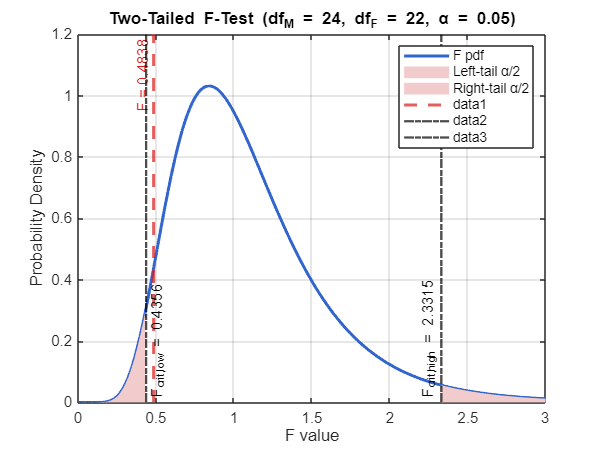

x = linspace(0, 3, 600);        % horizontal axis for F values
y = fpdf(x, dfM, dfF);          % theoretical F density curve

figure;%('Color','w','Position',[100 100 980 420]);
plot(x, y, 'Color',[0.2 0.4 0.8], 'LineWidth',2, 'DisplayName','F pdf'); 
hold on; grid on;

% --- Shade rejection regions ---
mask_left  = x <= Fcrit_low2;
mask_right = x >= Fcrit_hi2;
fill([x(mask_left) fliplr(x(mask_left))], [y(mask_left) zeros(1,sum(mask_left))], ...
     [0.95 0.8 0.8], 'EdgeColor','none', 'DisplayName','Left-tail α/2');
fill([x(mask_right) fliplr(x(mask_right))], [y(mask_right) zeros(1,sum(mask_right))], ...
     [0.95 0.8 0.8], 'EdgeColor','none', 'DisplayName','Right-tail α/2');

% --- Mark observed F value and critical values ---
xline(F_stat, 'r--', 'LineWidth', 2, 'Label', sprintf('F = %.4f', F_stat), ...
       'LabelHorizontalAlignment','left','LabelVerticalAlignment','top','Color',[0.85 0.1 0.1]);
xline(Fcrit_low2,  'k-.', 'LineWidth', 1.5, 'Label', sprintf('F_{crit,low} = %.4f', Fcrit_low2), ...
       'LabelHorizontalAlignment','right','LabelVerticalAlignment','bottom');
xline(Fcrit_hi2,   'k-.', 'LineWidth', 1.5, 'Label', sprintf('F_{crit,high} = %.4f', Fcrit_hi2), ...
       'LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom');

xlabel('F value');
ylabel('Probability Density');
title(sprintf('Two-Tailed F-Test (df_M = %d, df_F = %d, α = 0.05)', dfM, dfF));
legend('show','Location','northeast','Orientation','vertical');
hold off;

**What these functions do**

- `fpdf(x,df1,df2)` is the **F pdf** for plotting.

- `fill()` colors the area under the curve to visually show the p-value.

- `xline()` drops annotated vertical reference lines

**Step 6. Decision (two-tailed, α=0.05)**

alpha = 0.05;

if (F_stat < Fcrit_low2) || (F_stat > Fcrit_hi2)
    decision = 'Reject H₀: Variances differ significantly.';
else
    decision = 'Fail to reject H₀: No significant difference in variances.';
end

fprintf('\n--- DECISION ---\n');


--- DECISION ---


fprintf('At α = %.2f: %s\n', alpha, decision);

At α = 0.05: Fail to reject H₀: No significant difference in variances.


**Step 7. Reflection and Key Takeaways**

fprintf('\nINTERPRETATION:\n');


INTERPRETATION:


fprintf('Because the observed F = %.3f lies between the critical values [%.3f, %.3f],\n', ...
        F_stat, Fcrit_low2, Fcrit_hi2);

Because the observed F = 0.484 lies between the critical values [0.436, 2.331],


fprintf('and p(two-tail) = %.4f > 0.05, we FAIL to reject H₀.\n', p_two);

and p(two-tail) = 0.0859 > 0.05, we FAIL to reject H₀.


fprintf('Conclusion: There is no statistically significant evidence that male and female\n');

Conclusion: There is no statistically significant evidence that male and female


fprintf('salary variances differ. In other words, salary variability appears similar\n');

salary variances differ. In other words, salary variability appears similar


fprintf('between genders in this sample.\n\n');

between genders in this sample.




fprintf('Practical takeaway:\n');

Practical takeaway:


fprintf('- The F-test compares two sample variances using their ratio.\n');

- The F-test compares two sample variances using their ratio.


fprintf('- Use it when you want to test equality of variances before a t-test.\n');

- Use it when you want to test equality of variances before a t-test.


fprintf('- The test is sensitive to normality — data should be roughly normal.\n');

- The test is sensitive to normality — data should be roughly normal.


fprintf('- If H₀ is not rejected, you may proceed assuming equal variances in a pooled t-test.\n');

- If H₀ is not rejected, you may proceed assuming equal variances in a pooled t-test.


fprintf('- If H₀ is rejected, use Welch’s t-test (unequal variances) instead.\n');

- If H₀ is rejected, use Welch’s t-test (unequal variances) instead.


**Interpretation**

- Because $p_{\textrm{two}-\textrm{tail}} \approx 0\ldotp 0858>0\ldotp 05$, we **fail to reject** H0

- There is **no statistically significant evidence** that the salary variances differ.

## Example 4.2 2-Sample t-Test

**Learning objectives: **By the end, you can:

- decide when to use the **pooled two-sample t-test** (assumptions!)

- compute pooled variance, **t**, **df**, **p-values**, and **critical t**

- build a **95% CI** for the mean difference

- interpret results in context (decision & practical meaning)

**Example**: A Minister of Economics investigates whether male and female public-sector salaries differ in their mean values. Variance testing showed equality of variances, so we use a **pooled t-test**.

Hypotheses: 

- $H_0 :\mu_M =\mu_F$ → Mean salaries are equal

- $H_1 :\mu_M \not= \mu_F$→ Mean salaries differ

Assumptions: 

- Independent random samples 

- Approximately normal populations 

- Equal population variances (verified)

**Detailed Breakdown of Core MATLAB Functions**

**Step 0. Initialization**

clear; clc; close all; 
% clear: removes variables from the workspace to avoid contamination.
% clc: clears the command window for a clean start.
% close all: closes any previously open figure windows.

**Step 1. Input Sample Data**

 Input salary data for males and females. Each list represents one independent random sample.

% salary_m : sample of male employees
salary_m = [ ...
    41324.8, 48981.2, 46244.3, 45907.6, 39473.4, 45970.6, 46835.3, 45856.4, ...
    45913.8, 56185.1, 38261.4, 55075.1, 45364.6, 41486.7, 49027.9, 38621.5, ...
    41950.7, 32228.6, 50662.3, 46330.7, 36324.5, 39874.2, 54694.8, 52152.8, 52744.3];
% salary_f : sample of female employees
salary_f = [ ...
    37915.9, 26981.5, 22803.0, 32279.8, 44772.5, 32336.9, 42252.8, 38217.0, ...
    35054.4, 40877.2, 32673.0, 42463.2, 37821.8, 38746.1, 34626.6, 20007.8, ...
    36671.8, 45671.9, 18093.7, 52163.6, 43207.3, 36158.7, 52314.6];
% numel()  : returns number of elements in a vector (sample size n)
nM = numel(salary_m);   % sample size for males
nF = numel(salary_f);   % sample size for females

**Step 2. Descriptive Statistics**

Purpose: summarize the data numerically before testing.Always begin by summarizing your data before running a hypothesis test.

meanM  = mean(salary_m);   % arithmetic mean of male sample
meanF  = mean(salary_f);   % arithmetic mean of female sample
stdM   = std(salary_m, 0); % sample standard deviation (denominator n−1)
stdF   = std(salary_f, 0);
varM   = var(salary_m, 0); % sample variance
varF   = var(salary_f, 0);
rangeM = range(salary_m);  % range = max - min
rangeF = range(salary_f);

% Organize summary stats in a comparison table
Tdesc = table([meanM; stdM; varM; rangeM; nM], ...
              [meanF; stdF; varF; rangeF; nF], ...
    'VariableNames', {'Male','Female'}, ...
    'RowNames', {'Mean','Std','Variance','Range','Count'});
disp('Descriptive Statistics (Sample):');

Descriptive Statistics (Sample):


disp(Tdesc);

                   Male         Female  
                __________    __________

    Mean             45500         36700
    Std             6178.7        8883.5
    Variance    3.8176e+07    7.8916e+07
    Range            23956         34221
    Count               25            23



**Step 3. Visual exploration: Boxplots and Histograms**

Always visualize data before testing to check approximate normality and see whether the variances look visually different.

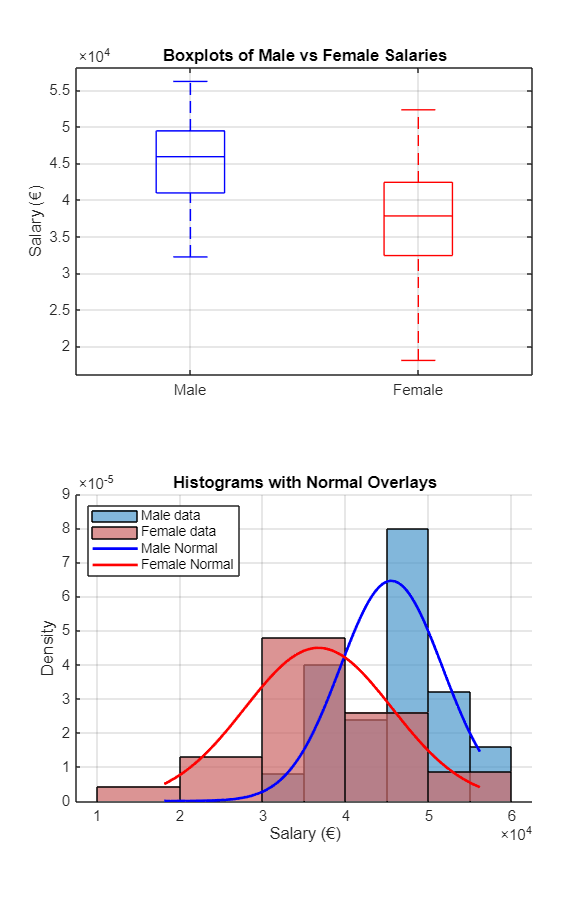

figure('Color','w','Position',[100 100 980 1500]);

% ---- (a) Boxplots ----
subplot(2,1,1);
boxplot([salary_m'; salary_f'], ...
        [repmat({'Male'}, nM, 1); repmat({'Female'}, nF, 1)], ...
        'Colors', ['b','r']);
title('Boxplots of Male vs Female Salaries');
ylabel('Salary (€)');
grid on;

% ---- (b) Histograms + normal overlays ----
subplot(2,1,2); hold on;
histogram(salary_m, 'Normalization','pdf', 'FaceColor',[0.3 0.6 0.8], 'FaceAlpha',0.7);
histogram(salary_f, 'Normalization','pdf', 'FaceColor',[0.8 0.4 0.4], 'FaceAlpha',0.7);
x = linspace(min([salary_m salary_f]), max([salary_m salary_f]), 300);
plot(x, normpdf(x, meanM, stdM), 'b-', 'LineWidth', 1.8);
plot(x, normpdf(x, meanF, stdF), 'r-', 'LineWidth', 1.8);
title('Histograms with Normal Overlays');
xlabel('Salary (€)'); ylabel('Density');
legend('Male data','Female data','Male Normal','Female Normal','Location','northwest');
grid on; hold off;

**Step 4. Compute t-Test (Equal Variances)**

Since the F-test confirmed equal variances, we use the **pooled t-test**. The test statistic compares the difference of means relative to variability across both samples.

% --- Step 4.1 Degrees of freedom ---
df = nM + nF - 2;       % total degrees of freedom = n₁ + n₂ − 2

% --- Step 4.2 Compute pooled variance (sp²) and pooled std (sp) ---
sp2 = ((nM - 1)*varM + (nF - 1)*varF) / df;   % weighted average of variances
sp  = sqrt(sp2);                              % pooled standard deviation

% --- Step 4.3 Compute t-statistic ---
diff_means = meanM - meanF;                   % difference in sample means
SE = sp * sqrt(1/nM + 1/nF);                  % standard error of mean difference
t_stat = diff_means / SE;                     % t statistic (signal/noise ratio)

% --- Step 4.4 Compute p-values ---
% tcdf(x,df): CDF of Student's t → gives P(T ≤ x)
p_two = 2 * (1 - tcdf(abs(t_stat), df));      % two-tailed p-value
p_one = p_two / 2;                            % one-tailed p-value (if directional)

% --- Step 4.5 Critical values for α = 0.05 ---
tcrit_one = tinv(1 - 0.05, df)               % one-tailed critical t

tcrit_one = 1.6787

tcrit_two = tinv(1 - 0.025, df)              % two-tailed critical t (α/2 = 0.025)

tcrit_two = 2.0129


% --- Step 4.6 95% Confidence Interval for (μ_M − μ_F) ---
CI_low  = diff_means - tcrit_two * SE;
CI_high = diff_means + tcrit_two * SE;

% --- Display numerical results ---
fprintf('\n--- Test Results ---\n');


--- Test Results ---


fprintf('t = %.4f | df = %d\n', t_stat, df);

t = 4.0107 | df = 46


fprintf('p(two-tail) = %.4f\n', p_two);

p(two-tail) = 0.0002


fprintf('95%% CI for (μ_M − μ_F): [%.1f , %.1f]\n', CI_low, CI_high);

95% CI for (μ_M − μ_F): [4383.0 , 13215.4]


**Step 5. Visualization t-Distribution with Critical Regions (Optional)**

Optional but helpful: visualize rejection regions and the observed t-statistic.

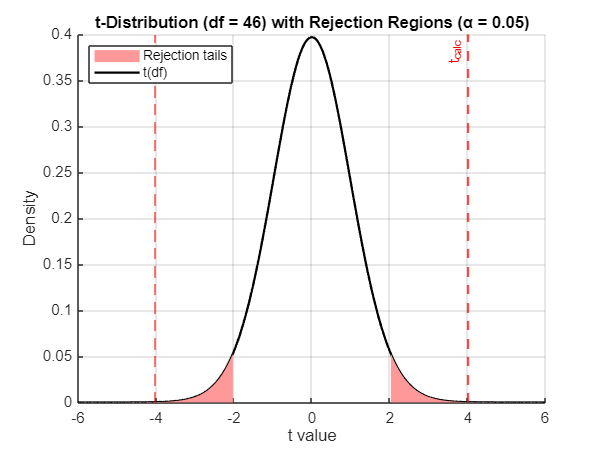

figure; 
hold on;
x = linspace(-6,6,400);         % t-axis from -6 to 6
y = tpdf(x, df);                % theoretical t distribution for given df
plot(x, y, 'k-', 'LineWidth', 1.5);  % draw the t curve

% Shade both rejection tails (2.5% each for α = 0.05 two-tailed)
area(x(x < -abs(tcrit_two)), y(x < -abs(tcrit_two)), ...
     'FaceColor',[1 0.6 0.6],'EdgeColor','none');
area(x(x >  abs(tcrit_two)), y(x >  abs(tcrit_two)), ...
     'FaceColor',[1 0.6 0.6],'EdgeColor','none');

% Draw vertical lines for observed t statistic
xline(t_stat,'r--','LineWidth',1.5,'Label','t_{calc}','LabelHorizontalAlignment','left');
xline(-t_stat,'r--');

title(sprintf('t-Distribution (df = %d) with Rejection Regions (α = 0.05)', df));
xlabel('t value'); ylabel('Density');
legend('t(df)','Rejection tails','Location','northwest');
grid on; hold off;

**Summary: **

- The graph shows the *t-distribution* under the null hypothesis that male and female salaries have the same mean.

- The shaded red areas represent the rejection regions for α = 0.05 (5% total).

- Our observed t = 4.01 is so far from 0 that it falls deep into the right-hand tail, where probability (area) is only 0.0002.

- This very small area is the **p-value**, which means such a result would occur by chance only 0.02% of the time if there were truly no difference.

- The 95% confidence interval ([4383, 13215]) shows that the true mean salary gap is likely between those values, and since 0 isn’t in that range, it confirms the difference is statistically significant.

**Step 6. Decision and Interpretation**

alpha = 0.05;
if p_two < alpha
    decision = "Reject H₀ → Mean salaries differ significantly.";
else
    decision = "Fail to reject H₀ → No significant mean difference detected.";
end

fprintf('\nDecision: %s\n', decision);


Decision: Reject H₀ → Mean salaries differ significantly.



fprintf(['\n--- Interpretation ---\n' ...
    'At α = 0.05 (two-tailed):\n' ...
    't(%d) = %.4f, p = %.4f\n' ...
    '95%% CI = [%.1f , %.1f]\n' ...
    '→ %s\n'], df, t_stat, p_two, CI_low, CI_high, decision);


--- Interpretation ---
At α = 0.05 (two-tailed):
t(46) = 4.0107, p = 0.0002
95% CI = [4383.0 , 13215.4]
→ Reject H₀ → Mean salaries differ significantly.



fprintf(['\nConclusion:\n' ...
    'Because p < 0.05, the null hypothesis of equal mean salaries is rejected.\n' ...
    'This indicates a statistically significant mean difference between male and\n' ...
    'female public-sector employees. The complaints of unequal pay appear valid.\n']);


Conclusion:
Because p < 0.05, the null hypothesis of equal mean salaries is rejected.
This indicates a statistically significant mean difference between male and
female public-sector employees. The complaints of unequal pay appear valid.


**Step 7. Reflection and Practical Use**

**When to use this test:**When comparing two **independent** groups (e.g., male vs female), and you’ve already checked that variances are **equal** (via an F-test).

**Why the pooled version:**If population variances are assumed equal, pooling both samples gives a more accurate estimate of common variability → slightly more statistical power.

**In this case:**

- Variances were equal (verified previously).

- Mean salaries differ → evidence supports inequality.

- **If variances were unequal:**You would instead use **Welch’s t-test**, which adjusts df and does not pool variances.

## **Example 4.3** **2-Sample t-Test (Welch)**

**Learning Objectives **

- Identify when to use Welch t-test

-  Compute t, df (Satterthwaite), p-values, and 95% CI 

- Present results with clear visuals and interpretation

A quality program coordinator wants to compare student satisfaction ratings between two departments (A vs B). Samples are independent and variances appear unequal, so use a Welch two-sample t-test. 

Hypotheses (two-tailed): 

- $H_0 :\mu_A =\mu_B$ → no difference in population means

- $H_1 :\mu_A \not= \mu_B$ → means differ

Why Welch? - When population variances are unequal and/or sample sizes differ, the pooled-variance t-test is inappropriate. Welch’s test uses a separate-variances standard error and the Satterthwaite df formula.

Decision rule at α = 0.05 (two-tailed): Reject H0 if `t` > t_{0.975, df} or p(two-tail) < 0.05

**Detailed Breakdown of Core MATLAB Functions**

**Step 0. Initialization**

clear; clc; close all; 
% clear: removes variables from the workspace to avoid contamination.
% clc: clears the command window for a clean start.
% close all: closes any previously open figure windows.

**Step 1. Input Data**

Two independent samples of satisfaction ratings (0–100 scale). Unequal variances were observed in preliminary checks ⇒ use Welch test.

depA = [72 64 60 68 77 68 75 72 70 74 68 75 72 72 69 58 71 78 57 82 76 70 83 75 66];
depB = [68 69 66 71 69 71 66 66 73 68 69 66 69 68 64 68 71 63 64 68 67 65 68 65];

nA = numel(depA);    % sample size for department A (25)
nB = numel(depB);    % sample size for department B (24)
fprintf('Sample sizes →  nA = %d,  nB = %d\n\n', nA, nB);

Sample sizes →  nA = 25,  nB = 24



**Step 2. Descriptive Statistics**

Summarise both groups before inference.

meanA = mean(depA);     meanB = mean(depB);
stdA  = std(depA,0);    stdB  = std(depB,0);
varA  = var(depA,0);    varB  = var(depB,0);
medA  = median(depA);   medB  = median(depB);
minA  = min(depA);      minB  = min(depB);
maxA  = max(depA);      maxB  = max(depB);
rngA  = range(depA);    rngB  = range(depB);

Desc = table( ...
  [meanA; stdA; varA; medA; minA; maxA; rngA; sum(depA); nA], ...
  [meanB; stdB; varB; medB; minB; maxB; rngB; sum(depB); nB], ...
  'VariableNames', {'DepA','DepB'}, ...
  'RowNames', {'Mean','Std (n-1)','Variance (n-1)','Median','Min','Max','Range','Sum','Count'} );
disp('Descriptive statistics:');

Descriptive statistics:


disp(Desc);

                       DepA      DepB 
                      ______    ______

    Mean               70.88    67.583
    Std (n-1)         6.5468    2.5007
    Variance (n-1)     42.86    6.2536
    Median                72        68
    Min                   57        63
    Max                   83        73
    Range                 26        10
    Sum                 1772      1622
    Count                 25        24



**Step 3. Visual Exploration (Boxplots + Histograms)**

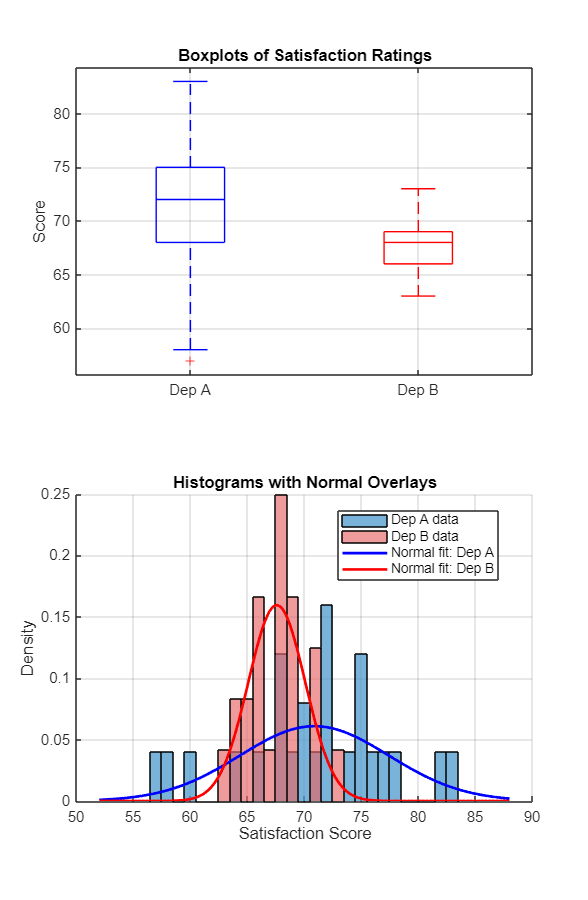

figure('Color','w','Position',[100 100 980 1500]);

% (a) Boxplots (handles unequal n robustly by using a group label vector)
subplot(2,1,1);
boxplot([depA'; depB'], [repmat({'Dep A'}, nA,1); repmat({'Dep B'}, nB,1)], ...
        'Colors', ['b','r']);
title('Boxplots of Satisfaction Ratings'); ylabel('Score');
grid on;

% (b) Histograms (density) + Normal overlays (fit to each sample)
subplot(2,1,2); hold on;
histogram(depA, 'Normalization','pdf', 'FaceColor',[0.3 0.6 0.8], 'FaceAlpha',0.75);
histogram(depB, 'Normalization','pdf', 'FaceColor',[0.9 0.4 0.4], 'FaceAlpha',0.65);
xx = linspace(min([depA depB])-5, max([depA depB])+5, 300);
plot(xx, normpdf(xx, meanA, stdA), 'b-', 'LineWidth',1.8);
plot(xx, normpdf(xx, meanB, stdB), 'r-', 'LineWidth',1.8);
title('Histograms with Normal Overlays');
xlabel('Satisfaction Score'); ylabel('Density');
legend('Dep A data','Dep B data','Normal fit: Dep A','Normal fit: Dep B','Location','best');
grid on; hold off;

**Step 4. Welch t-Test Computation (Unequal Variances)**

Standard error uses each group’s own variance.

SE_welch = sqrt(varA/nA + varB/nB);            % separate-variances SE
diff_means = meanA - meanB;                    % difference of means
t_stat = diff_means / SE_welch;                % test statistic

% Satterthwaite approximation for degrees of freedom
num = (varA/nA + varB/nB)^2;
den = (varA^2/(nA^2*(nA - 1))) + (varB^2/(nB^2*(nB - 1)));
df = num / den;                                % fractional df (≈ 31)

% p-values (two- and one-tailed)
p_two = 2 * (1 - tcdf(abs(t_stat), df));       % two-tailed
p_one = p_two / 2;                             % one-tailed alternative

% critical t-values for α = 0.05
tcrit_two = tinv(1 - 0.025, df);               % two-tail
tcrit_one = tinv(1 - 0.05,  df);               % one-tail

% 95 % confidence interval for (μA − μB)
CI_low  = diff_means - tcrit_two * SE_welch;
CI_high = diff_means + tcrit_two * SE_welch;

% summary table resembling Excel’s output
WelchTable = table( ...
 [meanA; varA; nA; 0; df; t_stat; p_one; tcrit_one; p_two; tcrit_two], ...
 [meanB; varB; nB; NaN; NaN; NaN; NaN; NaN; NaN; NaN], ...
 'RowNames', {'Mean','Variance','Observations','Hypothesized Mean Diff', ...
               'df','t Stat','P(T<=t) one-tail','t Critical one-tail', ...
               'P(T<=t) two-tail','t Critical two-tail'}, ...
 'VariableNames', {'DepA','DepB'} );
disp('Welch t-test summary (Excel-style):'); disp(WelchTable);

Welch t-test summary (Excel-style):
                                DepA       DepB 
                              ________    ______

    Mean                         70.88    67.583
    Variance                     42.86    6.2536
    Observations                    25        24
    Hypothesized Mean Diff           0       NaN
    df                            31.1       NaN
    t Stat                      2.3458       NaN
    P(T<=t) one-tail          0.012769       NaN
    t Critical one-tail         1.6954       NaN
    P(T<=t) two-tail          0.025537       NaN
    t Critical two-tail         2.0392       NaN



fprintf('\n95%% CI for (μA − μB): [%.2f , %.2f]\n', CI_low, CI_high);


95% CI for (μA − μB): [0.43 , 6.16]


**Step 5. Visualisation of t-Distribution with Rejection Regions (Optional)**

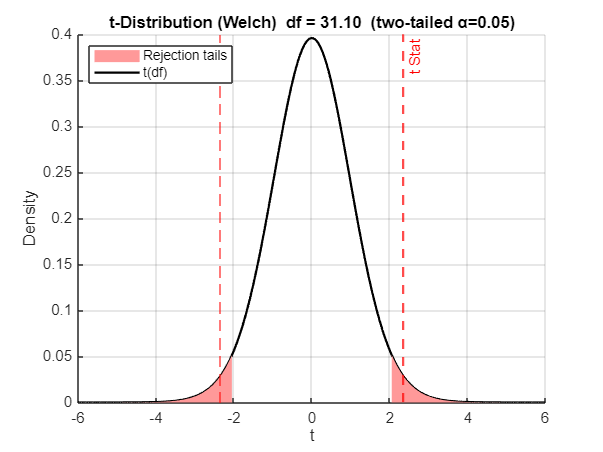

figure;hold on
x = linspace(-6,6,600);
y = tpdf(x, df);
plot(x, y, 'k-', 'LineWidth', 1.5);
area(x(x < -tcrit_two), y(x < -tcrit_two), 'FaceColor',[1 0.6 0.6], 'EdgeColor','none');
area(x(x >  tcrit_two), y(x >  tcrit_two), 'FaceColor',[1 0.6 0.6], 'EdgeColor','none');
xline(t_stat,   'r--','t Stat','LineWidth',1.5);
xline(-t_stat,  'r--');
title(sprintf('t-Distribution (Welch)  df = %.2f  (two-tailed α=0.05)', df));
xlabel('t'); ylabel('Density');
legend('t(df)','Rejection tails','Location','northwest');
grid on; hold off;

**Step 6. Decision and Interpretation (α = 0.05, two-tailed)**

alpha = 0.05;
if p_two < alpha
    decision = "Reject H₀ → Departments differ significantly in mean satisfaction.";
else
    decision = "Fail to reject H₀ → No statistically significant difference found.";
end

fprintf('\n--- Decision & Interpretation ---\n');


--- Decision & Interpretation ---


fprintf('t = %.4f, df = %.2f, p(two-tail) = %.4f\n', t_stat, df, p_two);

t = 2.3458, df = 31.10, p(two-tail) = 0.0255


fprintf('95%% CI = [%.2f , %.2f]\n', CI_low, CI_high);

95% CI = [0.43 , 6.16]


fprintf('Decision: %s\n', decision);

Decision: Reject H₀ → Departments differ significantly in mean satisfaction.



fprintf('\nInterpretation:\n');


Interpretation:


fprintf('Welch’s t-test accounts for unequal variances and slightly unequal sample sizes.\n');

Welch’s t-test accounts for unequal variances and slightly unequal sample sizes.


fprintf('Here, p(two-tail) = %.3f and |t| = %.2f ≤ tcrit = %.2f → %s\n', p_two, abs(t_stat), tcrit_two, decision);

Here, p(two-tail) = 0.026 and |t| = 2.35 ≤ tcrit = 2.04 → Reject H₀ → Departments differ significantly in mean satisfaction.


fprintf('Practically, average satisfaction levels are not significantly different at α = 0.05.\n');

Practically, average satisfaction levels are not significantly different at α = 0.05.


fprintf('=======================================================================\n');

**Step 7.  Reflection**

**When to use Welch’s test:**Whenever sample sizes or variances differ between groups and equality of variance cannot be assumed.

**Why it matters:**Unlike the pooled test, Welch’s does not underestimate standard errors when spreads differ, leading to more reliable inferences.

**In this example:**The mean satisfaction scores of departments A and B are *not significantly different* (p > 0.05).Although averages appear close, statistical evidence does not support a real difference.

**Key takeaway:**Welch’s t-test is the safer, general-purpose two-sample test; the pooled test is a special case used only when variances are confidently equal.

## Example 4.4 Paired** t-Test **

**Learning Objectives:** After completing this exercise, students will be able to:

- Understand the logic behind the **Paired t-test **(for dependent samples)

- Perform a **hypothesis test** on dependent samples using MATLAB.

- Interpret the **t-statistic**, **p-value**, and **confidence interval**.

- Visualize the data using **boxplots**, **histograms**, and **t-distribution curves**.

- Summarize results and explain their statistical meaning clearly.

**Example**: A medical doctor wants to determine whether a particular treatment  has an effect on heart rate (H.R.) at rest. Twenty-two (22) random people were measured before and after six months of treatment.

Because the same individuals are measured twice, the two samples are **dependent, **each "Before" value is paired with an "After" value. This dependency is why we use a **Paired t-test**, not an independent one.

**Hypotheses** (Two-tailed): 

- $H_0 :\mu_d =0$ → Mean difference (Before − After) is zero (no treatment effect) 

- $H_1 :\mu_d \not= 0$ → Mean difference is not zero (treatment changes heart rate)

Significance level: $\alpha =0\ldotp 05$

Interpretation: If $\left|t\right|>t_{\textrm{critica}}$ or $p<0\ldotp 05$, reject $H_0$ and conclude that the treatment affects heart rate at rest.

**Detailed Breakdown of Core MATLAB Functions**

**Step 0. Initialization**

clear; clc; close all; 
% clear: removes variables from the workspace to avoid contamination.
% clc: clears the command window for a clean start.
% close all: closes any previously open figure windows.

**Step 1. Input Data**

Data are two related samples: heart rate (bpm) before and after treatment.

HR_before = [74 76 75 75 73 75 76 75 75 79 73 78 75 74 76 73 74 71 77 75 72 73];
HR_after  = [74 77 72 74 73 73 73 72 75 74 72 72 72 77 78 75 67 70 74 75 74 77];

% n is the number of paired observations (i.e., the number of people).
n = numel(HR_before);

fprintf('Number of paired observations (participants): n = %d\n\n', n);

Number of paired observations (participants): n = 22




% Each observation i corresponds to the same individual before and after
% treatment. This dependency is what defines a *paired* design.

**Step 2. Descriptive Statistics**

Compute basic descriptive statistics for both conditions. 

- mean(x): arithmetic mean. 

- std(x,0): sample standard deviation, using n−1 denominator (unbiased).

**Why divide by (n − 1)?**

When you take a **sample** from a population, your sample mean (x̄) is just an estimate of the true population mean (μ). Because you estimated the mean from the same data, you’ve already “used up” 1 degree of freedom, one piece of information.

So you divide by **(n − 1)** instead of n to **compensate for that lost information**.That’s called **Bessel’s correction**.

**In simple terms:**

- Dividing by **n** assumes you already know the population mean (μ).

- Dividing by **(n − 1)** acknowledges that you only know the **sample mean**, which is less precise.

The (n−1) correction makes your standard deviation estimate **a little bigger**, which makes it an **unbiased estimate** of the true population spread.

**“Unbiased”, what does that mean?**

An estimator is *unbiased* if, across many repeated samples, it gives you the correct average value of the true population quantity.

So:

- `std(x, 1)` (dividing by n) → **biased**: underestimates spread on average.

- `std(x, 0)` (dividing by n−1) → **unbiased**: correctly estimates population variability on average.

Mean_before = mean(HR_before);      % average heart rate before treatment
Mean_after  = mean(HR_after);       % average heart rate after treatment
Std_before  = std(HR_before,0);     % sample standard deviation before
Std_after   = std(HR_after,0);      % sample standard deviation after

% Display a summary table with mean, std, and sample size for both groups.
Desc = table([Mean_before; Std_before; n], ...
              [Mean_after; Std_after; n], ...
              'VariableNames', {'Before','After'}, ...
              'RowNames', {'Mean','StdDev','SampleSize'});

disp('--- DESCRIPTIVE SUMMARY TABLE ---');

--- DESCRIPTIVE SUMMARY TABLE ---


disp(Desc);

                  Before    After 
                  ______    ______

    Mean          74.727    73.636
    StdDev        1.8818    2.4985
    SampleSize        22        22




fprintf(['Interpretation:\n',...
    '- The mean heart rate before treatment is %.2f bpm, after is %.2f bpm.\n',...
    '- We will test whether this observed difference is statistically significant.\n\n'], ...
    Mean_before, Mean_after);

Interpretation:
- The mean heart rate before treatment is 74.73 bpm, after is 73.64 bpm.
- We will test whether this observed difference is statistically significant.



**Step 3. Visualization, Boxplot and Histograms**

Always visualize data distributions before hypothesis testing. This step helps check normality, spread, and any outliers visually.

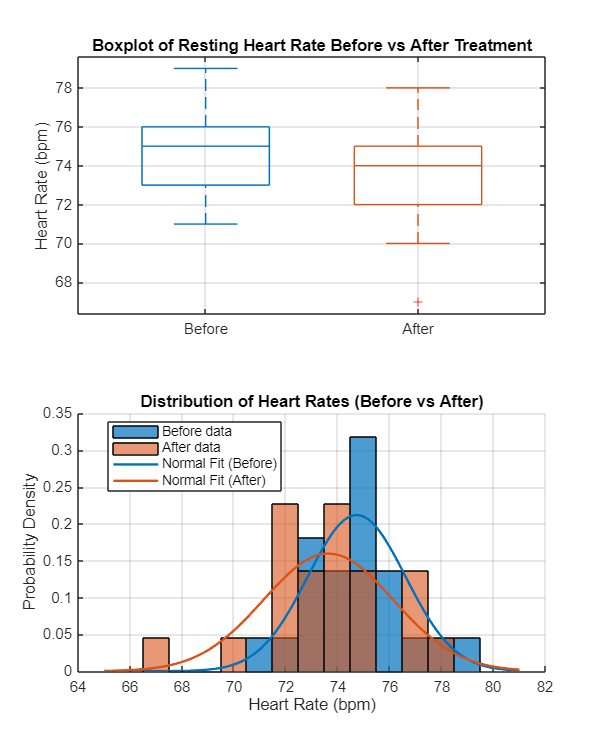

figure('Color','w','Position',[100 100 1200 1500]);

% ---- (a) Boxplot comparison ----
subplot(2,1,1);
colors = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];  % MATLAB default blue/red

% boxplot(Y): draws box-and-whisker plots.
% Each column of Y is treated as a separate group.
boxplot([HR_before', HR_after'], ...
        'Labels', {'Before','After'}, ...       % X-axis group labels
        'Colors', colors, ...                   % assign group colors
        'Widths', 0.6);                         % width of boxplots

title('Boxplot of Resting Heart Rate Before vs After Treatment');
ylabel('Heart Rate (bpm)');
grid on;

% ---- (b) Histograms + normal distribution overlays ----
subplot(2,1,2); hold on;

% histogram(x,'Normalization','pdf'): plots a histogram scaled as a 
% probability density function (so the area = 1).
histogram(HR_before, 'Normalization','pdf', ...
           'FaceColor',colors(1,:), 'FaceAlpha',0.7);
histogram(HR_after,  'Normalization','pdf', ...
           'FaceColor',colors(2,:), 'FaceAlpha',0.6);

% Overlay theoretical normal distributions for each group.
% normpdf(x,mu,sigma): returns values of the normal PDF.
x = linspace(min([HR_before HR_after])-2, max([HR_before HR_after])+2, 400);
plot(x, normpdf(x, Mean_before, Std_before), 'Color',colors(1,:), 'LineWidth',1.6);
plot(x, normpdf(x, Mean_after,  Std_after),  'Color',colors(2,:), 'LineWidth',1.6);

title('Distribution of Heart Rates (Before vs After)');
xlabel('Heart Rate (bpm)'); ylabel('Probability Density');
legend('Before data','After data','Normal Fit (Before)','Normal Fit (After)','Location','best');
grid on; hold off;


% Visual analysis note:
% If both distributions overlap substantially, we might expect a non-significant result.

**Step 4. Compute Paired Differences and t-Test Statistic**

The paired t-test is mathematically equivalent to performing a one-sample t-test on the **differences** between pairs.

D = HR_before - HR_after;    % vector of differences for each participant
dbar = mean(D);              % mean difference
sd_d = std(D,0);             % sample std of differences (uses n−1)
SE_d = sd_d / sqrt(n);       % standard error of the mean difference
df = n - 1;                  % degrees of freedom for t-test

% Test statistic formula:
%   t = d̄ / (s_d / √n)
t_stat = dbar / SE_d;
% Set significance level (two-tailed test)
alpha = 0.05;

% tinv(p,df): inverse t-distribution function.
% Returns t-critical value such that P(T <= tcrit) = p for given df.
% For a two-tailed test, we use 1−α/2.
t_crit = tinv(1 - alpha/2, df);

% tcdf(x,df): cumulative distribution function of t.
% Gives P(T <= x). For a two-tailed test, p = 2 * [1 − P(|T| ≤ |t_stat|)].
p_two = 2 * (1 - tcdf(abs(t_stat), df));

% Display computed statistics.
fprintf('\n--- PAIRED T-TEST RESULTS ---\n');


--- PAIRED T-TEST RESULTS ---


fprintf('Mean difference (Before−After) = %.3f bpm\n', dbar);

Mean difference (Before−After) = 1.091 bpm


fprintf('Std deviation of differences (s_d) = %.3f\n', sd_d);

Std deviation of differences (s_d) = 2.877


fprintf('Standard Error (SE_d) = %.3f\n', SE_d);

Standard Error (SE_d) = 0.613


fprintf('Degrees of freedom (df) = %d\n', df);

Degrees of freedom (df) = 21


fprintf('t-statistic = %.3f\n', t_stat);

t-statistic = 1.779


fprintf('t-critical (two-tailed, α=0.05) = ±%.3f\n', t_crit);

t-critical (two-tailed, α=0.05) = ±2.080


fprintf('p-value (two-tailed) = %.3f\n', p_two);

p-value (two-tailed) = 0.090



% Decision logic: compare p-value or t-statistic to criteria.
if p_two < alpha
    decision = 'Reject H₀ → The treatment significantly changed heart rate.';
else
    decision = 'Fail to reject H₀ → No statistically significant effect detected.';
end
fprintf('Decision: %s\n', decision);

Decision: Fail to reject H₀ → No statistically significant effect detected.


**Step 5. 95% Confidence Interval for Mean Difference**

Confidence interval formula: $\textrm{CI}=\bar{d} \pm t_{a/2,v} \frac{\hat{\sigma_d } }{\sqrt{n}}$

%% Step 5. Confidence interval for mean difference (μ_d)
% Purpose:
%   Quantify the uncertainty around the sample mean difference (d̄).
%   The interval shows where the true mean difference μ_d is likely to lie
%   with 95% confidence.

% Formula:
%   CI = d̄ ± t_(α/2, df) × (s_d / √n)

% Compute lower and upper bounds:
CI_low  = dbar - t_crit * SE_d;
CI_high = dbar + t_crit * SE_d;

% Display the CI numerically:
fprintf('\n--- 95%% Confidence Interval for Mean Difference (μ_d) ---\n');


--- 95% Confidence Interval for Mean Difference (μ_d) ---


fprintf('CI = [%.3f , %.3f] bpm\n', CI_low, CI_high);

CI = [-0.185 , 2.366] bpm



% Create a small, labeled table for easy viewing:
CITable = table(dbar, SE_d, t_crit, CI_low, CI_high, ...
    'VariableNames', {'MeanDiff','StdError','tCritical','LowerBound','UpperBound'});
disp('--- Confidence Interval Summary ---');

--- Confidence Interval Summary ---


disp(CITable);

    MeanDiff    StdError    tCritical    LowerBound    UpperBound
    ________    ________    _________    __________    __________

     1.0909     0.61338      2.0796       -0.18468       2.3665  




% Interpret the interval in plain language:
if CI_low <= 0 && CI_high >= 0
    fprintf('Interpretation:\n');
    fprintf('  0 lies within the CI → the true mean difference could be zero.\n');
    fprintf('  Therefore, we fail to reject H₀ at α = 0.05.\n');
else
    fprintf('Interpretation:\n');
    fprintf('  0 is NOT within the CI → the treatment likely changed heart rate.\n');
    fprintf('  Therefore, reject H₀ at α = 0.05.\n');
end

Interpretation:


  0 lies within the CI → the true mean difference could be zero.


  Therefore, we fail to reject H₀ at α = 0.05.


**Key takeaway**

- The **paired t-test CI** estimates the *mean within-person change*.

- If **0 is inside** → no statistically significant effect.

- If **0 is outside** → significant effect.

- The CI conveys not just “significant or not,” but the *magnitude and direction* of the treatment effect.

**Step 6. Visualize t-Distribution with Rejection Regions (Optional)**

Purpose: show graphically where the calculated t-value lies relative to the rejection thresholds (t_crit).

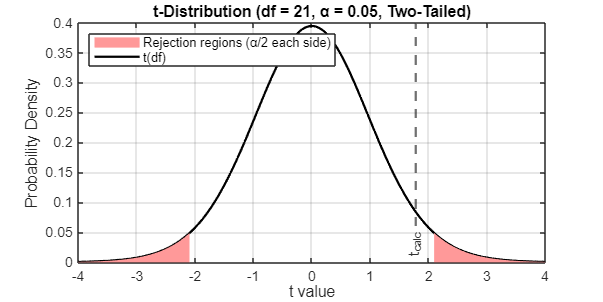

x = linspace(-4,4,400);     % range of t values for plotting
y = tpdf(x,df);             % t-distribution density for df degrees of freedom

figure('Color','w','Position',[100 100 900 450]);
plot(x, y, 'k-', 'LineWidth', 1.5); hold on;

% area(): fills regions under the curve to show rejection zones.
area(x(x < -t_crit), y(x < -t_crit), 'FaceColor',[1 0.6 0.6], 'EdgeColor','none');
area(x(x >  t_crit), y(x >  t_crit), 'FaceColor',[1 0.6 0.6], 'EdgeColor','none');

% xline(): vertical reference lines.
% We mark the observed t-statistic for clarity.
xline(t_stat,'--','Color',[0.2 0.2 0.2],'LineWidth',1.5,...
    'Label','t_{calc}','LabelHorizontalAlignment','center',...
    'LabelVerticalAlignment','bottom');

title(sprintf('t-Distribution (df = %d, α = 0.05, Two-Tailed)', df));
xlabel('t value'); ylabel('Probability Density');
legend('t(df)','Rejection regions (α/2 each side)','Location','northwest');
grid on; hold off;

**Step 7. Interpretation**

fprintf('\n--- INTERPRETATION ---\n');


--- INTERPRETATION ---


fprintf('At α = 0.05:\n');

At α = 0.05:


fprintf('  |t| = %.3f, tcrit = %.3f.\n', abs(t_stat), t_crit);

  |t| = 1.779, tcrit = 2.080.



if abs(t_stat) > t_crit
    fprintf('→ |t| > tcrit, Reject H₀.\n');
    fprintf('There is significant evidence that the treatment changed resting heart rate.\n');
else
    fprintf('→ |t| < tcrit, Fail to reject H₀.\n');
    fprintf('There is insufficient evidence that the treatment affected resting heart rate.\n');
end

→ |t| < tcrit, Fail to reject H₀.


There is insufficient evidence that the treatment affected resting heart rate.



fprintf('95%% Confidence Interval = [%.2f , %.2f] bpm.\n', CI_low, CI_high);

95% Confidence Interval = [-0.18 , 2.37] bpm.


fprintf('If this interval includes zero, the mean difference could be zero (no change).\n');

If this interval includes zero, the mean difference could be zero (no change).



% Create a compact final summary table for reports.
Results = table(n, dbar, sd_d, SE_d, df, t_stat, t_crit, p_two, ...
                CI_low, CI_high, string(decision), ...
    'VariableNames', {'n','MeanDiff','StdDiff','StdError','df','t_stat','t_crit',...
                      'p_value','CI_Lower','CI_Upper','Decision'});

disp('--- FINAL SUMMARY TABLE ---');

--- FINAL SUMMARY TABLE ---


disp(Results);

    n     MeanDiff    StdDiff    StdError    df    t_stat    t_crit    p_value     CI_Lower    CI_Upper                                  Decision                              
    __    ________    _______    ________    __    ______    ______    ________    ________    ________    ____________________________________________________________________

    22     1.0909      2.877     0.61338     21    1.7785    2.0796    0.089799    -0.18468     2.3665     "Fail to reject H₀ → No statistically significant effect detected."




fprintf('\nConclusion:\n');


Conclusion:


fprintf('The paired t-test evaluates whether the average within-person change in\n');

The paired t-test evaluates whether the average within-person change in


fprintf('heart rate is significantly different from zero. Here, with p = %.3f, we %s\n',...
        p_two, lower(decision));

heart rate is significantly different from zero. Here, with p = 0.090, we fail to reject h₀ → no statistically significant effect detected.


fprintf('If this were part of a clinical trial, we would conclude that the treatment\n');

If this were part of a clinical trial, we would conclude that the treatment


fprintf('did NOT have a statistically significant effect on resting heart rate at α = 0.05.\n');

did NOT have a statistically significant effect on resting heart rate at α = 0.05.


fprintf('==========================================================================\n');

**Step 8. Practical Summary**

**Why we used a paired t-test:**

- The same individuals were measured **before and after** treatment.

- This creates **dependent (paired) data**, because each “before” value is linked to an “after” value from the same person.

- A paired t-test specifically accounts for this relationship, it analyses **the changes within people**, not differences between unrelated groups.

**What the test does conceptually:**

- It reduces each person’s two scores to a single **difference score (Before − After)**.

- Then it tests whether the **average of those differences** is significantly different from zero.

- This approach removes the effect of individual differences (e.g., people having naturally higher or lower heart rates).

**Why not use a 2-sample t-test:**

- A 2-sample test assumes two **independent groups**, which isn’t true here since each person appears in both conditions.

- Using an independent test here would ignore the within-subject link and inflate error, making results less reliable.

**When to use the paired t-test in general:**

- Before/after studies (pre-test vs post-test on same subjects).

- Matched-pairs designs (e.g., twins, or participants matched on key traits).

- Any situation where two measurements come from **the same experimental units** under different conditions.

**What we learned from this example:**

- The treatment slightly lowered mean heart rate, but not significantly, showing how variability within people can mask small mean changes.

- Even if group means differ visually, statistical evidence is required to confirm a real effect.

- The paired t-test gives that evidence while properly accounting for the dependency in the data.

**Key takeaway:**The paired t-test is the right tool when comparing two related measurements on the same subjects.It focuses on *changes within individuals*, giving a more sensitive and fair test of an intervention’s true effect.